# Low lying spectrum and corresponding eigenstates of hydrogen and helium atoms and problem of three interacting electrons 

Temo Vekua

March 29, 2021

This Live Script is intended for physics and chemistry students studying fundamentals of many-body quantum mechanics, and for educators who wish to integrate computation in the foundational quantum mechanics labs. Starting with analytically solvable case of hydrogen atom and reproducing numerically low lying energy spectrum and corresponding wavefunctions, we next study hellium atom with two electrons. Even though for helium atom system sizes studied are small (with $N\le 16$ discrete points in each direction), one can see how explicit numerically exact calculation, without variational approximate methods, suggests shell models to interpret level-structure of many-body problem and leads to parahelium and orthohelium states naturally. The final section is dedicated to constructing many-body wavefucntion obeying Pauli principle for 3 interacting electrons, without decomposing three-body coordinate wavefunctions into the product of single-partical orbitals.

## Numerical simulation of hydrogen atom

Nonrelativistic Hamiltonian describing hydrogen atom at rest can be written as


$$(1) \quad H_{hydrogen}=\frac{m_e}{\hbar^2} \Big(  \frac{e^2}{4\pi\varepsilon_0} \Big)^2\Big( -\frac{a_0^2}{2} \vec \nabla^2 - \frac{a_0}{r}\Big),$$


where $m_e$ is a mass of electron (treating proton mass as infinite), $\hbar$ is a reduced Planck's constant, $e$ is proton's charge, $\varepsilon_0$ is a vacuum permittivity, $r=\sqrt{r_x^2+r_y^2+r_z^2}$ is a distance from the origin (proton's location), $\vec \nabla^2$ is a 3D Laplacian and Bohr radius is


$$(2) \quad a_0=\frac{\hbar^2 4\pi \varepsilon_0 }{m_e e^2}\simeq 0.5  \text{\AA} =0.5\cdot10^{-10}m.$$


Analytical expression of hydrogen atom's $n$-th ($n=1,2,3,\cdots$, with $n=1$ corresponding to the ground state is) bound state energy (without relativistic corrections [1]) is

$(3) \quad E_n=-\frac{m_e}{2 \hbar^2}  \frac{e^4}{(4\pi\varepsilon_0)^2} \frac{1}{n^2}$.

The (coordinate) wavefunction for the lowest energy (ground) state of electron in the hydrogen atom is

$(4) \quad \psi_{0}(\vec r)=\frac{1}{\sqrt{\pi a_0^3}}e^{-r/a_0}$.

The radial probability density in the ground state is

$(5) \quad P_r=4\frac{r^2}{a_0^3}e^{-2r/a_0}$.

Let's plot radial dependencies in Eq. (4) and Eq. (5).

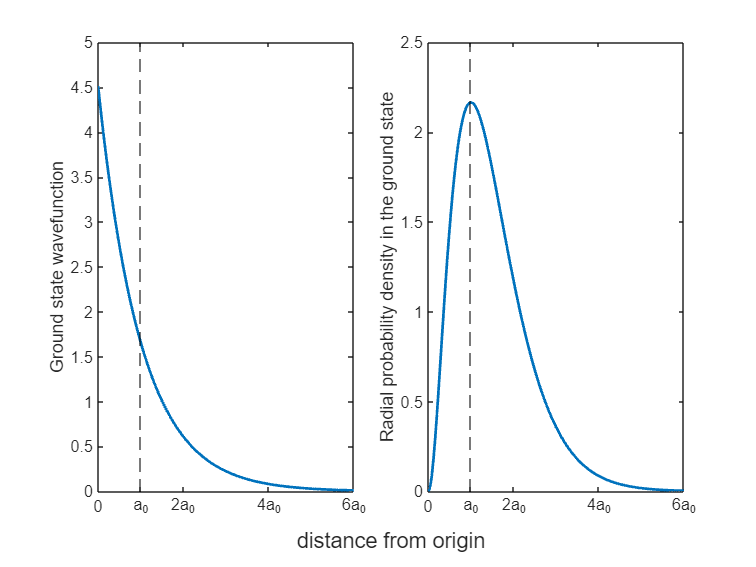

clf;
a_0=1/4; % distance will be measured in units of 4*a0
r=0:0.01:1.5;
clc;
t = tiledlayout(1,2,'TileSpacing','Compact');
nexttile
plot(r, exp(-r/a_0)/sqrt(pi*a_0^3))
xline(a_0,'--k')
xticks([0, a_0, 0.5, 1, 1.5])
xticklabels({'0','a_0', '2a_0','4a_0','6a_0'})
ylabel('Ground state wavefunction')
nexttile
plot(r, 4*r.^2.*exp(-2*r/a_0)/a_0^3)
xline(a_0,'--k')
xticks([0, a_0, 0.5, 1, 1.5])
xticklabels({'0','a_0', '2a_0','4a_0','6a_0'})
ylabel('Radial probability density in the ground state')
xlabel(t,'distance from origin')

integral(@(r) 4*r.^2.*exp(-2*r/a_0)/a_0^3,0,1.4)

ans = 0.9990

With probablility of 99.9% electron is localized within $R=1.4\cdot 4a_0$ sphere in the ground state. This estimate will help us to determine optimal linear length $L$ of 3D mesh for accurate numerical simulation of the ground state wavefunction and energy.

During simulations we will use dimensionless distance $r/(4a_0)\to r$ (distance will be measured in units of four times Bohr radius). We will solve numerically following eigenvalue problem:


$$(*)\quad \Big( -\frac{1}{2} \vec \nabla^2 - \frac{4}{r}\Big) \psi(\vec r) =E\psi(\vec r)$$


and to convert obtained dimensionless energies $E$ into standard energy units we will multiply them by factor:

 $(6) \quad -\frac{E_0}{8}= \frac{m_e}{\hbar^2} \Big(  \frac{e^2}{16\pi\varepsilon_0} \Big)^2$,

equal to $2.72\cdot 10^{-19}J$, or in Electronvolts $1.7eV$, or in hartrees $\frac{1}{16} Ha$.

Let's check that dimension of Eq. (6) is Joule, using symbolic math toolbox .

u = symunit; % create symbolic variable u that carries collection of units
eqn = u.J == u.m_e*u.e^4/(u.hbar^2*u.e_0^2); %u.J carries Joule, dimension of energy in SI
checkUnits(eqn,'Compatible')

ans = logical
   0


Hydrogen atom's bound states occupy more volume with increasing $n$, see [this](https://en.wikipedia.org/wiki/Atomic_orbital) (shell radius grows fast with energy level $n$ as $a_0n^2$). Hence, finite size volume $L^3$ (which we impose to perform numerical simulations) will influence energy of the level more with increasing $n$. In addition, finite-size effects remove Coulomb ($n^2$, without considering spin degrees of freedom) degeneracy of hydrogen energy levels.  

L = 2.8;  % Interval Length in each direction in units of 4 Bohr radia. L=1 is a distance of one 4 Bohr radia, ~2 angstroms
N = 26;  % Number of coordinate points in each direction
x = linspace(-L/2, L/2, N).'; % 1D coordinate column vector
dx = x(2) - x(1); % Coordinate step 

e    = ones(N,1);  % a column of 1-s with N elements       
Lap_1D  = spdiags([e -2*e e],[-1 0 1],N,N) / dx^2;  % sparse NxN matrix with vector -2*e along the main diagonal
% and vector e along upper and lower diagonals, so called 3-point Laplacian

% Below we show two equivalent ways to define 3D Laplacian corresponding to a particle. 
% Both forms are identical to sum of Laplacians of 3 one-dimensional particles

% Lap_2D = kron(Lap_1D,speye(N))+kron(speye(N),Lap_1D); % 2D Laplacian, speye(N) is sparce NxN identity matrix
% H_K3D = -1/2*(kron(Lap_2D,speye(N))+kron(speye(N^2),Lap_1D)); % -1/2 times 3D Laplacian 

Lap_1 = kron(kron(Lap_1D,speye(N)),speye(N)); % sparse N^3xN^3 matrix
Lap_2 = kron(kron(speye(N),Lap_1D),speye(N));
Lap_3 = kron(kron(speye(N),speye(N)),Lap_1D);
H_K3D = -1/2*(Lap_1+Lap_2+Lap_3);

[X,Y,Z]=meshgrid(x);  % X,Y,Z are 3D tensors of size [N,N,N] encoding 3D coordinate grid
% X encodes x coordinates of N^3 lattice points, Y encodes y coordinates and Z -> z
% coordinates
syms x1 x2 x3 y1 y2 y3 z1 z2 z3   % define symbolic variables for better clarity what meshgrid function does
x_s=[x1 x2 x3].'            % define symbolic column

$$x\_s = \left(\begin{array}{c} x_{1}\\ x_{2}\\ x_{3} \end{array}\right)$$

y_s=[y1 y2 y3].'

$$y\_s = \left(\begin{array}{c} y_{1}\\ y_{2}\\ y_{3} \end{array}\right)$$

z_s=[z1 z2 z3].'

$$z\_s = \left(\begin{array}{c} z_{1}\\ z_{2}\\ z_{3} \end{array}\right)$$

[X_s,Y_s, Z_s]=meshgrid(x_s,y_s,z_s)

$$\left(\begin{array}{ccc} x_{1} & x_{2} & x_{3}\\ x_{1} & x_{2} & x_{3}\\ x_{1} & x_{2} & x_{3} \end{array}\right)$$

$$\left(\begin{array}{ccc} x_{1} & x_{2} & x_{3}\\ x_{1} & x_{2} & x_{3}\\ x_{1} & x_{2} & x_{3} \end{array}\right)$$

$$\left(\begin{array}{ccc} x_{1} & x_{2} & x_{3}\\ x_{1} & x_{2} & x_{3}\\ x_{1} & x_{2} & x_{3} \end{array}\right)$$

$$\left(\begin{array}{ccc} y_{1} & y_{1} & y_{1}\\ y_{2} & y_{2} & y_{2}\\ y_{3} & y_{3} & y_{3} \end{array}\right)$$

$$\left(\begin{array}{ccc} y_{1} & y_{1} & y_{1}\\ y_{2} & y_{2} & y_{2}\\ y_{3} & y_{3} & y_{3} \end{array}\right)$$

$$\left(\begin{array}{ccc} y_{1} & y_{1} & y_{1}\\ y_{2} & y_{2} & y_{2}\\ y_{3} & y_{3} & y_{3} \end{array}\right)$$

$$\left(\begin{array}{ccc} z_{1} & z_{1} & z_{1}\\ z_{1} & z_{1} & z_{1}\\ z_{1} & z_{1} & z_{1} \end{array}\right)$$

$$\left(\begin{array}{ccc} z_{2} & z_{2} & z_{2}\\ z_{2} & z_{2} & z_{2}\\ z_{2} & z_{2} & z_{2} \end{array}\right)$$

$$\left(\begin{array}{ccc} z_{3} & z_{3} & z_{3}\\ z_{3} & z_{3} & z_{3}\\ z_{3} & z_{3} & z_{3} \end{array}\right)$$


U=-4./sqrt(X.^2+Y.^2+Z.^2);   % U is three dimensional tensor here with size(U)= [N,N,N], 
% with N^3 elements, number of lattice points in 3D space
U=spdiags(U(:),0, N^3,N^3);   % U becomes sparse diagonal matrix of linear dimension N^3 

H=H_K3D+U;                    % matrix corresponding to the total dimensionless hamiltonian Eq. (*) 
[V,E] = eigs(H,15,'smallestreal'); % find eigs.
[E,ind] = sort(diag(E));       % convert diagonal matrix E to a column vector and sort low to high
V = V(:,ind);                  % rearrange corresponding eigenvectors.

E % show energies 

E =    -7.6504
   -1.4115
   -1.4115
   -1.4115
   -0.7434
    1.2040
    1.2040
    1.2040
    1.8894
    1.8894



V_XYZ=reshape(V(:,1)/dx^(3/2),N,N,N); % for plotting reshape eigenfunctions (column vectors) into 3D tensors
V_XY=V_XYZ(:,:,N/2); % selecting Z=0 section
[X2,Y2]=meshgrid(x);
t1=tiledlayout(1,2);
nexttile
surf(X2,Y2,V_XY) %sometimes invert sign in front of V_XY
xlim([-1.4 1.4])
ylim([-1.4 1.4])
zlim([0 4.3])
xlabel(t1, 'unit of spacing is 4a_0')
zlabel('Wavefunction')
title('Simulated wavefunction')
daspect([1 1 1])
psi_0=1/sqrt(pi*0.25^3)*exp(-4*sqrt(X2.^2+Y2.^2+x(N/2)^2)); %analytical expression for a_0=0.25
nexttile
surf(X2,Y2,psi_0)
xlim([-1.4 1.4])
ylim([-1.4 1.4])
zlim([0 4.3])
title('Analytical wavefunction')
daspect([1 1 1])

For $L=20$, and different $N$, energies of first 15 lowest levels are given in the table below (non-converged values for $N=120$ are represented by NaN). Note, with increasing $N$ all values converge to their true thermodynamic limit values.

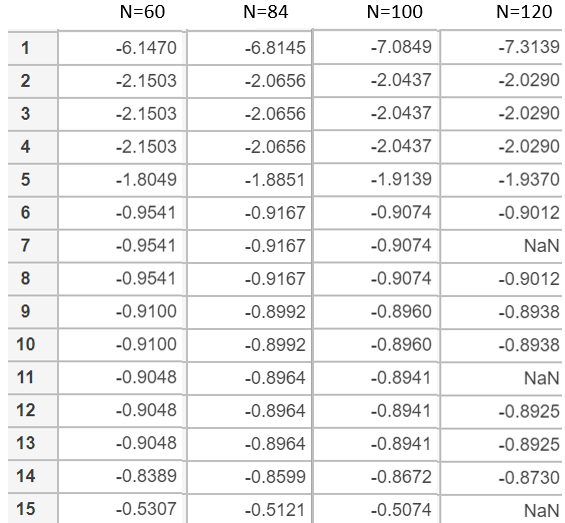

True energy (continuum limit in infinite space) values are  $n=1: E=-8$ (singlet $l=0$ s-state, its enegry converges to $-8$ with increasing $N$, for $N=200$, $E=-7.72$), $n=2, E= -2$ (4 states $l=1$ triplet and $l=0$ singlet) , $n=3, E= -8/9$ (9 states, quintuplet, triplet, and singlet), $n=4, E= -0.5$ (16 states). 

Since electron in the ground state is localized close to the origin (with probablility of 99.9% electron is localized within $r=1.4\cdot 4a_0$ sphere in the ground state), taking $L=2.8$ gives much better matching with true thermodynamic ground state energy value. Already for $N=20$, $E=-7.44$, for $N = 64$, $E=-7.93$, for $N=100$, $E=-7.97$ and for$N=200$, $E=-7.99$. 

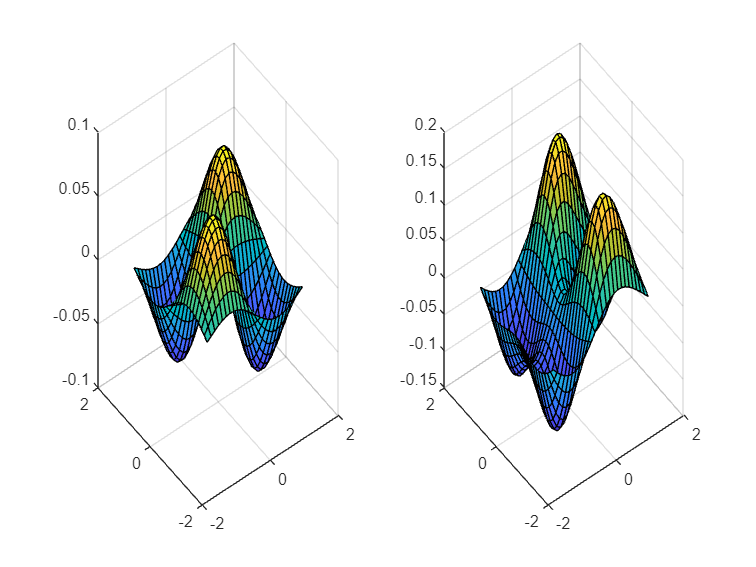

tiledlayout(2,2)
for j=2:5
   V_XYZj=reshape(V(:,j)/dx^(3/2),N,N,N);
   V_XYj=V_XYZj(:,:,N/2); % selecting Z=0 section
   nexttile
   surf(X2,Y2,V_XYj)
end

tiledlayout(2,2)
for j=6:9
   V_XYZj=reshape(V(:,j)/dx^(3/2),N,N,N);
   V_XYj=V_XYZj(:,:,N/2); % selecting Z=0 section
   nexttile
   surf(X2,Y2,V_XYj)
end
tiledlayout(2,2)
for j=10:13
   V_XYZj=reshape(V(:,j)/dx^(3/2),N,N,N);
   V_XYj=V_XYZj(:,:,N/2); % selecting Z=0 section
   nexttile
   surf(X2,Y2,V_XYj)
end
tiledlayout(1,2)
for j=14:15
   V_XYZj=reshape(V(:,j)/dx^(3/2),N,N,N);
   V_XYj=V_XYZj(:,:,N/2); % selecting Z=0 section
   nexttile
   surf(X2,Y2,V_XYj)
end

## Numerical simulation of helium atom

Now we trurn to simulation of helium atom with $Z=2$, in the approximation of an infinitely heavy nucleus (neglecting the mass polarization term, which, when neede, is easy to include as it does not increase computational complexity). Contrary to the hydrogen atom case, there is no closed-form solution of the two-electron Schrodinger equation for helium atom, described by following hamiltonian: 


$$(7) \quad H_{helium}=\frac{m_e}{\hbar^2} \Big(  \frac{e^2}{4\pi\varepsilon_0} \Big)^2\Big( -\frac{a_0^2}{2} \vec \nabla_1^2 - -\frac{a_0^2}{2} \vec \nabla_2^2 -\frac{2a_0}{r_1} -\frac{2a_0}{r_2}    +\frac{a_0}{ |\vec r_1-\vec r_2|}\Big).$$


The last term in Eq. (7) describes mutual Coulomb repulsion between the two electrons of helium atom.

We will again use dimensionless distance $r/(4a_0)\to r$ and solve following eigenvalue problem fot he dimensionless hamiltonian:


$$(**) \quad \Big( -\frac{1}{2} \vec \nabla_1^2- \frac{1}{2} \vec \nabla_2^2- \frac{8}{r_1} - \frac{8}{r_2}  +\frac{4}{|\vec r_1-\vec r_2|} \Big) \psi(\vec r_1, \vec r_2) =E\psi(\vec r_1, \vec r_2)$$


and to convert dimensionless energies $E$ obtained from eigenvalue problem Eq. (**) to standard energy units we will multiply them by  a factor given in Eq. (6) (equal to $1.7eV$).

Helium atom hamiltonian given in Eq. (7), acts on the wavefunction that is defined in 6D space (with 3D coordinate space corresponding to each particle). If $N$ is a number of discrete points along each of the spacial direction, then dimension of matrix corresponding to hamiltonian will be $N^6$x$N^6$ and matrix will be real (due to time-invariance of the problem) and hence symmetric (due to hermiticity of matrices corresponding to observables). Eigenvectors of real and symmetric matrices can always be represented by real and orthonormal set of vectors.  

A total two-particle wavefunction (accounting both for coordinate and spin degrees of freedom of two particles) can always be represented as a product of coordinate wavefunction and spin wavefunction (this is not always possible for three and more particles, see section on three electron case below),


$$(8) \quad \Psi^{electrons}_{s_1,s_2}(\vec r_1, \vec r_2)=\psi(\vec r_1, \vec r_2)\sigma(s_1,s_2).$$


Pauili exclusion principle requires antisymmetry under simultaneous exchange of spins and coordinates of electrons

 
$$(9) \quad \Psi^{electrons}_{s_1,s_2}(\vec r_1, \vec r_2)=-  \Psi^{electrons}_{s_2,s_1}(\vec r_2, \vec r_1).$$


In order that such separable (in spin and coordinate parts Eq. (8)) wavefunctions satisfy antisymmetry condition Eq. (9) only two options exist: when exchanging two particles coordinates and spins $r_1 \leftrightarrow r_2, \,\, s_1 \leftrightarrow s_2$ either coordinate wavefunction is symmetric and spin wavefunction is antisymmetric (spin-singlet state $\sigma_0(s_1,s_2)=(|\uparrow_1\rangle\otimes |\downarrow_2\rangle -|\downarrow_1\rangle \otimes |\uparrow_2\rangle)/\sqrt{2}$), or vice verca, coordinate wavefunction is antisymmetric and spin part is symmetric (spin-triplet state).

The eigenvectors of Eq. (**) satisfy the following condition (unless different parity eigenstates are energetically degenerate and computer returns some linear superposition of them without definite parity, cases that can be observed if we switch off Coulomb repulsion between electrons):


$$\psi(\vec r_2, \vec r_1)=\pm \psi(\vec r_1, \vec r_2).$$


We will see that for small system sizes that we will simulate helium's ground state coordinate wavefunction is symmetric with respect to exchanging coordinates of the two electrons $\psi_0(\vec r_1, \vec r_2) =\psi_0(\vec r_2, \vec r_1)$, hence for small size simulations the ground state corresponds to parahelium (spin-singlet state, instead of orthohelium spin-triplet state that is known from observations to be the true ground state of Helium atom in thermodynamic limit, consistent with the Hund's rule). Ground-state single-particle density shows spherical symmetry (with the caviet that we are using 3D cubic finite lattice for simulations).

For small size lattices, wavefunctions of first few lowest excited states are antisymmertic with respect to exchanging two electrons' coordinates, hence they correspond to spin-triplet states. These facts have intuitive explanation in shell model. Shell model is based on a single-electron picture: solve for one electron, like in the case of hydrogen atom above, and then distribute many electrons in the energy states of single-electron problem according to Pauli principle. In the ground state of helium for small system sizes that we simulate both electrons occupy $1s$ lowest orbital, hence they must form spin-singlet state. In the lowest excited states two electrons occupy both$1s$ and $2s$ (with spherical symmetry of single-particle density) or $1s$ and $2p$ (without spherical symmetry of single-particle density) orbitals and spin configurations can be singlet as well as triplet states for these cases depending on the symmetry of the coordinate wavefunction. True ground state of the helium atom (ground state in thermodynamic limit) corresponds to the 1s 2s state (orthohelium) with antisymmetric coordinate wavefunction that has a node at $x_1=x_2$, and hence Coulomb repulsion between electrons is minimized.

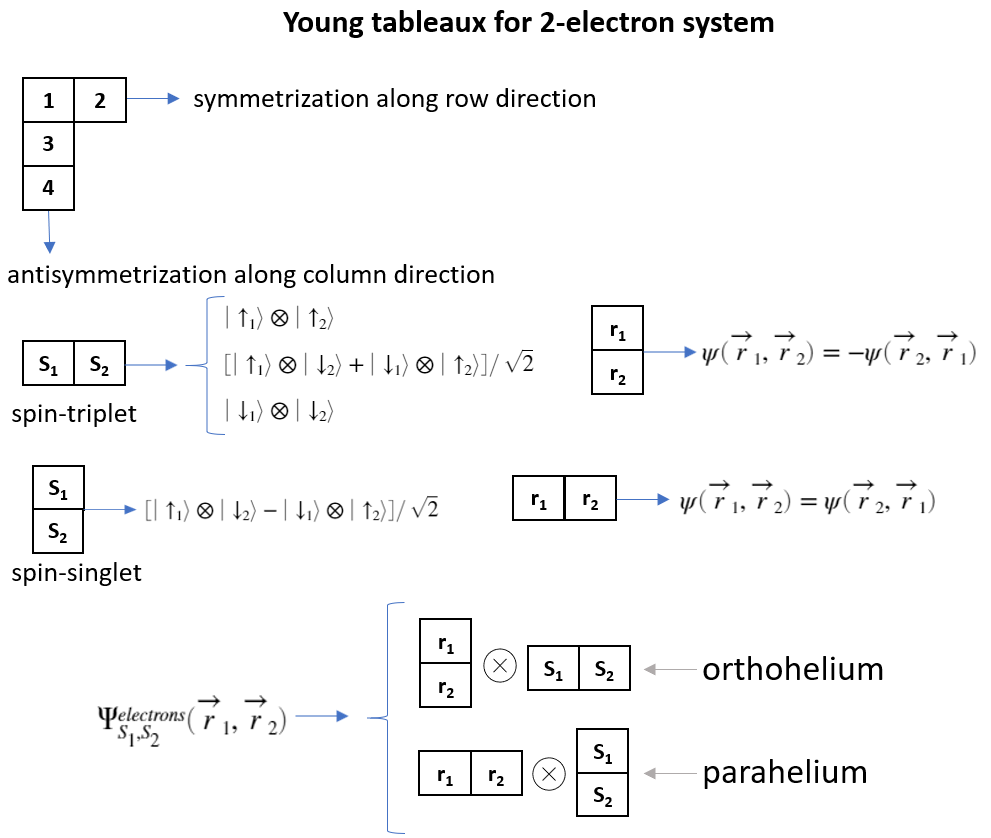

We will also study single-particle (one-body) density in the ground state and the lowest excited states of helium atom,

$(10)\quad \rho_{\alpha}(\vec r)=  \int d^3{\vec r'} |\psi_{\alpha}(\vec r,\vec r')|^2,$ with $\alpha=0$ indicating the ground state. 

$\rho_{\alpha}(\vec r)$ is the probability of finding an electron (when system is described by a two-electron state $\psi_{\alpha}$) in the volume element around vector $\vec r$, whilst another electron is anywhere.

L = 2;  % Interval Length in each direction in units of 4 Bohr radia. L=1 is a distance of 4 Bohr radia, ~2 angstroms
N = 10;  % Number of coordinate points in each direction
x = linspace(-L/2, L/2, N).'; % Coordinate column vector in x direction
dx = x(2) - x(1); % Coordinate step 


e    = ones(N,1); % a column of ones with N elements       
Lap_1D  = spdiags([e -2*e e],[-1 0 1],N,N) / dx^2;       % 1D Laplacian
Lap_2D = kron(Lap_1D,speye(N))+kron(speye(N),Lap_1D);    % 2D Laplacian
Lap_3D = kron(Lap_2D,speye(N))+kron(speye(N^2),Lap_1D);  % 3D Laplacian 

[X,Y,Z]=meshgrid(x); % three-dimensional mesh
% X, Y and Z are 3-dimensional tensors
U = -8./sqrt(X.^2+Y.^2+Z.^2);   % U here is three dimensional tensor with size(U)= [N,N,N]
U = spdiags( kron(U(:),ones(N^3,1))+kron(ones(N^3,1),U(:)), 0, N^6,N^6);   
% U in left-hand side becomes sparse diagonal matrix of linear dimension N^6, 
% accounting for Coulomb attraction of two electrons by helium nucleus

U_12=4./sqrt(0.0000001+ (kron(X(:),ones(N^3,1))-  kron(ones(N^3,1),X(:))).^2 ... 
    + (kron(Y(:),ones(N^3,1))-  kron(ones(N^3,1),Y(:))).^2 ... 
    +(kron(Z(:),ones(N^3,1))-  kron(ones(N^3,1),Z(:))).^2); % inter-electron interaction
% we choose some small number (1e-7) to avoid a divergence of a matrix when coordinates of 
% two electrons are equal 
H_K   = -(1/2)*(kron(Lap_3D,speye(N^3))+kron(speye(N^3),Lap_3D));
% Kinetic energy part of two electrons
H=H_K+U+spdiags(U_12,0,N^6,N^6);

[V,E] = eigs(H,5,'smallestreal'); % find eigs.
[E,ind] = sort(diag(E));       % convert diagonal matrix E to a column vector and sort low to high.
V = V(:,ind);                  % rearrange corresponding eigenvectors.

E % show energies 

E =   -30.9508
  -24.0627
  -24.0627
  -24.0627
  -22.7311



% Next we will calculate single-particle density in ground states of para and orthohelium (in Z=0 plane) and plot it
tiledlayout(1,2)
for j=[1,5] % j=1 is ground state of parahelim, j=5 we expect to becom ground state of orthohelium in thermodynamic limit
    psij=reshape(V(:,j),N^3,N^3);
    rho=diag(psij'*psij);  % this is a lattice version of continuum definition Eq. (10)
    rho=reshape(rho,N,N,N) % reshape to study single-particle density in Z=0 (x-y) plane below
    rho=rho(:,:,N/2);      % single-particle density in Z=0 plane in the state psij
    [X2,Y2]=meshgrid(x);
    nexttile
    surf(X2,Y2,rho/dx^2)
    view([0 90]) % uncomment this line for 2D view
    daspect([1,1,1])
    zlim([0 1.8])
end

rho = rho(:,:,1) =

   1.0e-04 *

    0.0001    0.0005    0.0014    0.0029    0.0042    0.0042    0.0029    0.0014    0.0005    0.0001
    0.0005    0.0026    0.0077    0.0161    0.0239    0.0239    0.0161    0.0077    0.0026    0.0005
    0.0014    0.0077    0.0239    0.0530    0.0817    0.0817    0.0530    0.0239    0.0077    0.0014
    0.0029    0.0161    0.0530    0.1251    0.2009    0.2009    0.1251    0.0530    0.0161    0.0029
    0.0042    0.0239    0.0817    0.2009    0.3335    0.3335    0.2009    0.0817    0.0239    0.0042
    0.0042    0.0239    0.0817    0.2009    0.3335    0.3335    0.2009    0.0817    0.0239    0.0042
    0.0029    0.0161    0.0530    0.1251    0.2009    0.2009    0.1251    0.0530    0.0161    0.0029
    0.0014    0.0077    0.0239    0.0530    0.0817    0.0817    0.0530    0.0239    0.0077    0.0014
    0.0005    0.0026    0.0077    0.0161    0.0239    0.0239    0.0161    0.0077    0.0026    0.0005
    0.0001    0.0005    0.0014    0.0029    0.0042    0.0

rho = rho(:,:,1) =

   1.0e-03 *

    0.0020    0.0076    0.0153    0.0224    0.0266    0.0266    0.0224    0.0153    0.0076    0.0020
    0.0076    0.0289    0.0578    0.0845    0.0999    0.0999    0.0845    0.0578    0.0289    0.0076
    0.0153    0.0578    0.1150    0.1661    0.1941    0.1941    0.1661    0.1150    0.0578    0.0153
    0.0224    0.0845    0.1661    0.2354    0.2700    0.2700    0.2354    0.1661    0.0845    0.0224
    0.0266    0.0999    0.1941    0.2700    0.3041    0.3041    0.2700    0.1941    0.0999    0.0266
    0.0266    0.0999    0.1941    0.2700    0.3041    0.3041    0.2700    0.1941    0.0999    0.0266
    0.0224    0.0845    0.1661    0.2354    0.2700    0.2700    0.2354    0.1661    0.0845    0.0224
    0.0153    0.0578    0.1150    0.1661    0.1941    0.1941    0.1661    0.1150    0.0578    0.0153
    0.0076    0.0289    0.0578    0.0845    0.0999    0.0999    0.0845    0.0578    0.0289    0.0076
    0.0020    0.0076    0.0153    0.0224    0.0266    0.0

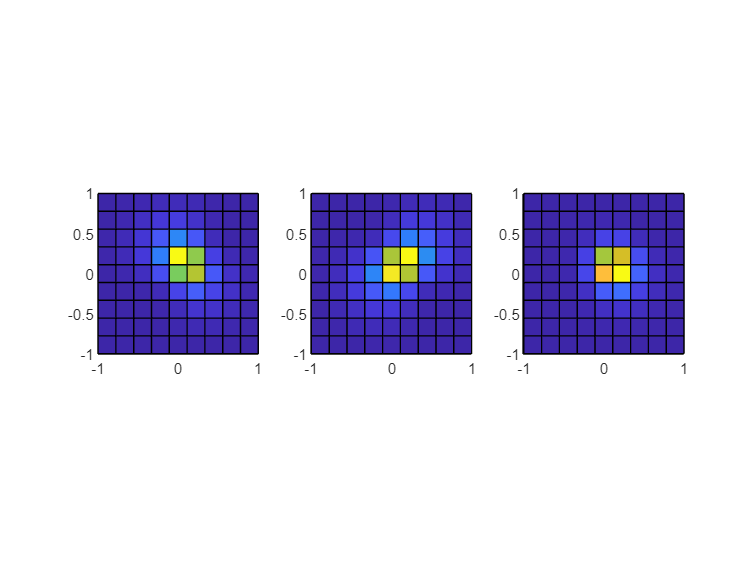


tiledlayout(1,3)
for j=2:4 % orbital momentum l=1 states
    psij=reshape(V(:,j),N^3,N^3);
    rho=diag(psij'*psij); 
    rho=reshape(rho,N,N,N);
    rho=rho(:,:,N/2);   % single-particle density in Z=0 plane in the state psij
    [X2,Y2]=meshgrid(x); % encode 2D mesh into X2 and Y2 matrices
    nexttile
    surf(X2,Y2,rho/dx^2)
    view([0 90]) % uncomment this line for 2D view
    daspect([1,1,1]) % equal aspect ration of axes
end



psi0=reshape(V(:,1),N^3,N^3); % reshape into matrix to check symmetry with respect to exchanging electrons' coordinates
psi0 % psi0 is a symmetric matrix, hence it describes ground state of parahelium (and also ground state of helium atom)

psi0 =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000  

psi1=reshape(V(:,2),N^3,N^3);
psi1 % psi1 is an antisymmetric matrix, hence it describes orthohelium

psi1 =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000  

psi2=reshape(V(:,3),N^3,N^3);
psi2 

psi2 =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000  

psi3=reshape(V(:,4),N^3,N^3);
psi3 

psi3 =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000  

psi4=reshape(V(:,5),N^3,N^3);
psi4 

psi4 =    -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000  


max(max(abs(psi0-psi0.')))  % result is negligibly small number, hence psi_0(r1,r2)=psi_0(r2,r1)  -> parahelium state

ans = 2.5969e-15

max(max(abs(psi1+psi1.')))  % result is negligibly small number, hence psi_1(r1,r2)=-psi_1(r2,r1) -> orthohelium state

ans = 4.0740e-15

max(max(abs(psi2+psi2.')))  % result is negligibly small number, hence psi_1(r1,r2)=-psi_1(r2,r1) -> orthohelium state

ans = 3.5374e-14

max(max(abs(psi3+psi3.')))  % result is negligibly small number, hence psi_1(r1,r2)=-psi_1(r2,r1) -> orthohelium state

ans = 3.0462e-15

max(max(abs(psi4+psi4.')))  % result is negligibly small number, hence psi_1(r1,r2)=-psi_1(r2,r1) -> orthohelium state

ans = 1.4322e-13

In finite systems ($N=10,12,14$ and $L=2$) the first 3 lowest excited states are degenerate in energy and are antisymmetric with respect to $\vec r_1\leftrightarrow \vec r_2$ (hence they should correspond to orthohelium). Single-particle densities show no spherical symmetry in these states, hence presumably these states in thermodynamic limit will converge to $1s2p$ orthohelium states with orbital momentum $l=1$. The fourth excited state (for the same system sizes as above) is a non-degenerate in energy, shows also antisymmetry with respect to $\vec r_1\leftrightarrow \vec r_2$ (hence it also describes orthohelium), however single-particle density calculated in this state shows same symmetry as the parahelium ground state. This state presumably converges in thermodynamic limit to $1s2s$ orthohelium state (true ground state of the Helium atom). Gap between the first three degenerate excited states and fourth non-degenerate state decreases with increasing system size and in accordance with experiments we expect that in thermodynamic limit the ground state in orthohelium configuration will be the non-degenerate $1s2s$ state, antisymetric with respec to $\vec r_1\leftrightarrow \vec r_2$ and with spherically symmetric eletron cloud. Yet, system sizes considered here are too small to make definitive claims on extrapolation to thermodynamic limit. 

In Fig. 1 we plot single-particle densities in the ground states of parahelium (left) and orthohelium configurations (the latter state for $N=14$ is the fourth excited state).

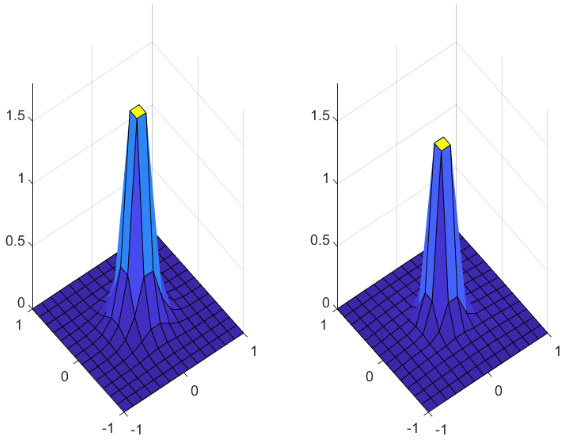

Figure 1: Single particle density in the $x-y$ plane in the ground state of parehelium (left) and orthohelium (right) for $N=14$ and $L=2$. In both cases electron density shows spherical symmetry ($l=0$ orbital momentum states). Particles are localized closer to origin in parahelium.

### Ground state energy of helium atom

Experimentally determined ground state energy of helium atom is equal to $5.8$-times ground state energy of hydrogen atom. Were electrons not interacting with each other, we would have obtained for helium ground state energy $8$-times the ground state energy of hydrogen atom, however Coulomb repulsion between electrons modiifes factor of 8 to 5.8. We will confirm this below. 

Due to exponential scaling of computational complexity with the number of quantum particles, in the case of helium atom we are limited to maximum number of points in each direction to $N_{helium,max }\sim \sqrt{N_{hydrogen, max}}$. On the other hand, electrons in the ground state are more localized to nucleus in helium, than in hydrogen atom. We will use this fact and will take $L=1$ for ground state calculations (3D box with a linear size of $4a_0$) to distribute all available $N_{helium,max}$ in the relevant region.

We calculated ground state energy for different values of $N$ (up to $N=16$ calculations are performed within a few minutes). Obtained results are presented in table below.

 

We introduce $x=1/N$ and fit $E_0$ to $x$ by the simplest linear model Poly1 (using curve fitting toolbox). Results are presented below.

 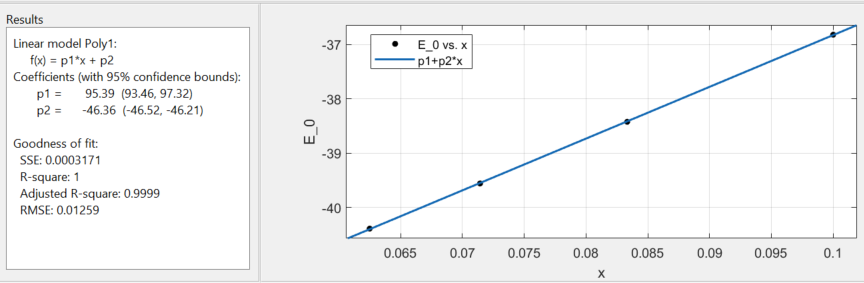

We are interested in thermodynamic limit $x\to 0$, where $E_0=p2$.

Ground state electron configuration energy of helium atom after linear extrapolatin of the results to the thermodynamic ($N\to \infty$) limit, within 95% confidence bounds is ($-78.5893eV$, $-79.1166eV$).  Experimentally determined ground state energy of the helium atom, −79.005151042(40) eV [2], falls within these bounds as a lucky coincidence.

## Three-electron problem

For 3 and more electrons (Lithium and heavier atoms) analogous to Eq. (**) 3D eigenvalue problems are computationally too heavy (for 3 electrons problem, hamiltonian matrix dimensions are $N^9$x $N^9$, daunting already for $N=10$) and approximate, but accurate variational methods or methods such as Kohn-Sham DFT  [3] (both in momentum and in real space formulations) exist. These approximate methods give very good description also for helium atom, and, since they are effectivey single-particle approaches, they are not plagued with exponential growth of the Hilbert space dimension with number of particles. 

 For 3 and more electrons hamiltonian matrix again will be real and symmetric, hence it will have a complete set of real orthonormal eigenvectors. Symmetry property of these coordinate wavefunctions with respect to exchanging coordinates of any two particles are more involved than for the case of 2 electrons. Purpose of the rest of this Livescript is construction of many-body states for three electron system (3 fermionic spin-1/2 particles), without decomposing many-body coordinate wavefunction into the product of single-particle ones (orbitals).  

We consider system of 3 interacting with each other electrons, with Hamiltonian not depending explicitely on the spins of electrons. We solve the following eigenvalue problem

$(***) \quad \Big( -\frac{1}{2} \sum^3_{j=1} \vec \nabla_j^2+\sum_{j<i}U(|\vec r_i-\vec r_j|) \Big) \psi(\vec r_1, \vec r_2, \vec r_3) =E\psi(\vec r_1, \vec r_2 ,\vec r_3)$,

where $\psi( \vec r_1,\vec r_2, \vec r_3)$ is a three-body coordinate eigenfunction of the Hamiltonian with a corresponding energy eigenvalue $E$. To reduce computational complexity we will assume the simplest 1D segment geometry $\vec r_j \to x_j$. At this point we do not specify symmetry properties of $\psi( x_1, x_2, x_3)$ with respect to exchanging any two coordinates. This specification will follow the discussion of the spin part of the total wavefunction (wavefunction accounting for both spin and coordinate degrees of freedom).

### Spin part

When total spin of the system is conserved, we can classify spin states by total spin value $S^T$: $\langle({\bf S}^T)^2 \rangle=\langle({\bf s}_1+{\bf s}_2+{\bf s}_3)^2 \rangle=S^T(S^T+1)$ and total magnetization value M: $\langle S_z^T\rangle=  \langle s_1^z+s_2^z+s_3^z\rangle=M$, $|S^T,M\rangle.$ Total spin of 3 spin-1/2 particles can take 2 distinct values $S^T=1/2, 3/2$. There are $2^3=8$ possible spin configurations for 3 electrons, 4 of them belong to $S^T=3/2$ (so called feromagnetic state) quadruplet (when all 3 electrons spins look in the same direction). These 4 states are denoted as $| 3/2,-3/2\rangle$, $| 3/2,-1/2\rangle$, $| 3/2,1/2\rangle$, and $| 3/2,3/2\rangle$. 

To consturct this quadruplet, we start from the highest-weight state (with all spins pointing up)

$| 3/2,3/2\rangle=|\uparrow_1 \rangle \otimes |\uparrow_2 \rangle\otimes |\uparrow_3 \rangle$, 

and act  on the highest-weight state by total spin-lowering operator $\sum^3_{j=1}s^-_j$ (and normalize to unity resulting state):

$| 3/2,1/2\rangle=\frac{1}{\sqrt{3}} \Big( |\downarrow_1 \rangle \otimes |\uparrow_2 \rangle\otimes |\uparrow_3 \rangle +|\uparrow_1 \rangle \otimes |\downarrow_2 \rangle\otimes |\uparrow_3 \rangle+|\uparrow_1 \rangle \otimes |\uparrow_2 \rangle\otimes |\downarrow_3 \rangle\Big )$,

$| 3/2,-1/2\rangle=\frac{1}{\sqrt{3}} \Big( |\downarrow_1 \rangle \otimes |\downarrow_2 \rangle\otimes |\uparrow_3 \rangle +|\downarrow_1 \rangle \otimes |\uparrow_2 \rangle\otimes |\downarrow_3 \rangle+|\uparrow_1 \rangle \otimes |\downarrow_2 \rangle\otimes |\downarrow_3 \rangle\Big )$,

$| 3/2,-3/2\rangle=|\downarrow_1 \rangle \otimes |\downarrow_2 \rangle\otimes |\downarrow_3 \rangle$.

All these states are symmetric with respect to exchanging any pair of spins participating in them. 

Coordinate wavefunction corresponding to these 4 (all spin-symmetric) states must by fully antisymmetric state: for non-interacting fermions (when many-body wavefunction is decompozable into the product of single-particle ones) such fermionic wavefunctions are called Slater determinants.

Now we construct spin states belonging to $S^T=1/2$ manifold. There should be 4 such states as well (two with $M=1/2$ and two with $M=-1/2$). Clearly when $S^T=1/2$, one of the electron's spin must look in the opposite direction from the two others. For $M=1/2$ there are only 2 (lineraly independent) such spin configurations (and similarly for $M=-1/2$).

First let's construct a spin-singlet between 1-st and 2-nd electrons: $\frac{1}{\sqrt{2}}\Big( |\uparrow_1\rangle  \otimes |\downarrow_2\rangle - | \downarrow_1 \rangle \otimes |\uparrow_2\rangle \Big)$.  In the spin-singlet state spins of electrons are oriented in opposite directions to each other. Next we add third electron in up-spin state (or in down-spin state for $M=-1/2$ case). 

$|\alpha\rangle=\frac{1}{\sqrt{2}}\Big( |\uparrow_1\rangle  \otimes |\downarrow_2\rangle - | \downarrow_1 \rangle \otimes |\uparrow_2\rangle \Big)\otimes |\uparrow_3\rangle$.

*Excercise:* Act on $|\alpha\rangle$ by $({\bf s}_1+{\bf s}_2+{\bf s}_3)^2$ and $s^z_1+ s^z_2+ s^z_3$ to confirm that it is an eigenstate of both operators with quantum numbers: $|1/2, 1/2\rangle$. 

Analogically we construct state $|\beta\rangle$, which is obtained by first forming a singlet between 1-st and 3-rd particles and then multiplying this singlet by 2-nd particle's up-spin state.

$|\beta\rangle=\frac{1}{\sqrt{2}}\Big( |\uparrow_1\rangle  \otimes |\uparrow_2\rangle\otimes |\downarrow\rangle - | \downarrow_1 \rangle \otimes |\uparrow_2\rangle \otimes |\uparrow_3\rangle \Big)$.

Third option (multiplying up-spin state of the first electron by the singlet formed between 2-nd and 3-rd particles) is not a new linearly independent state from the previous two, as 

$(11)\quad |\gamma\rangle=    \frac{1}{\sqrt{2}}  |\uparrow_1\rangle \otimes \Big (    |\uparrow_2\rangle \otimes |\downarrow_3\rangle  -  |\downarrow_2\rangle \otimes |\uparrow_3\rangle \Big)   =|\beta\rangle -|\alpha\rangle$.

In general (as showed by Wigner), for $N_e$ electrons, there are 


$$(11a)\quad \frac{(2S^T+1)N_e!}{(\frac{N_e}{2}-S^T)!(\frac{N_e}{2}+S^T+1)!}$$


linearly independent spin states for a given values of $S^T$ and $S^T_z$, where $0\le S^T\le N/2$ and $-S^T\le S^T_z\le S^T$.

By construction $|\alpha\rangle$ is antisymmetric with respect to exchanging spins of 1-st and 2-nd electrons. We can construct an (normalized) eigenstate of both $({\bf s}_1+{\bf s}_2+{\bf s}_3)^2$ and $s^z_1+ s^z_2+ s^z_3$  operators that will be symmetric with respect to exchanging spins of 1-st and 2-nd electrons and have the same quantum numbers $|1/2,1/2 \rangle$ as $|\alpha\rangle$:

$|\tilde \alpha \rangle= const(2| \beta\rangle -|\alpha\rangle  )=\frac{1}{\sqrt{6}}\Big(  |\uparrow_1\rangle  \otimes |\downarrow_2 \rangle \otimes |\uparrow_3\rangle+  |\downarrow_1\rangle  \otimes |\uparrow_2 \rangle \otimes |\uparrow_3\rangle -2  |\uparrow_1\rangle  \otimes \uparrow_2 \rangle \otimes |\downarrow_3\rangle \Big)$.

One can check that states $|\alpha\rangle$ and $|\tilde \alpha\rangle$ are orthogonal to each other: $\langle \alpha |\tilde\alpha\rangle=0$.

Note, it is impossible to construct a spin state (solely written in terms of spin variables of 3 particles) that at the same time will be symmetric with $s_1 \leftrightarrow s_2$, and antisymmetric with $s_1\leftrightarrow s_3$ and also antisymmetric with $s_2\leftrightarrow s_3$. To prove this statement let's represent arbitrary spin state of 3-particles as:

$\sum_{s_1,s_2,s_3} A_{s_1,s_2,s_3} |s_1\rangle \otimes |s_2 \rangle \otimes |s_3 \rangle$,

where summation is with all $s_j=\uparrow, \downarrow$.

Then we have to prove that it is impossible to have nonzero 3D tensor (tensor with 3 indices) that is symmetric with respect to exchanging its first two indices (dimensions) and at the same time is antisymmetric with respect to exchanging its firts and third as well as second and third indices (dimensions).

Claim: 

if following relations hold for a 3D tensor $A_{s_1,s_2,s_3}=A_{s_2,s_1,s_3}$, $A_{s_1,s_2,s_3}=-A_{s_3,s_2,s_1}$, and $A_{s_1,s_2,s_3}=-A_{s_1,s_3,s_2}$, 

then $A=0$.

Proorf:

$A_{s_1,s_2,s_3}=-A_{s_3,s_2,s_1}=A_{s_3,s_1,s_2}=A_{s_1,s_3,s_2}=-A_{s_1,s_2,s_3}=0$.

 Similar arguments explain the reason why for $N_e$ electrons, with $N_e>2$, a total many-electron wavefunction corresponding to $S^T<N_e/2$ is not separable into the product of spin part and coordinate part, $\Psi_{S^T<\frac{N_e}{2}}\neq \sigma(s_1,s_2,\cdots s_{N_e}) \cdot \psi(x_1,x_2,\cdots x_{N_e})$, hence coordinate wavefunctions (solutions of many-body Shrodinger equations for $N_e>2$) corresponding to $S^T<N_e/2$ states must be necessarily **degenerate**.

### Pseudo many-body case: Three-electron coordinate wavefunction separable into product of single electron orbitals 

Given two orthogonal states $|\alpha\rangle$/ $|\tilde \alpha \rangle$that are antisymmetric / symmetric with $s_1 \leftrightarrow s_2$, we can follow a standard procedure to construct full 3-electron wavefunction for the case when coordinate part of three-body wavefunction is separable into the product of single particle ones (orbitals). Wigner (1959) has suggested how to construct $N_e$-electron wavefunctions satisfying the Pauli principle, starting from orbital products, by taking suitable “dual” or “associated” irreducible representations of separate spatial and spin functions (for details see [4]). Let's assume that 3 electrons do not interact with each other, $U=0$, and hence, the total Hamiltonian in the left-hands-de of Eq. (***) is represented as a direct sum: $H(x_1,x_2,x_3)=H(x_1)+H(x_2)+H(x_3)$. We will construct the lowest energy three-electron state obeying Pauli principle. If a ground state coordinate wavefunction of a single particle hamiltonian $H(x_j)$ is $\phi_0(x_j)$ (so called lowest energy orbital), then ground state of 3-electron coordinate wavefunction must involve both the ground state $\phi_0(x_j)$ and also first excited state $\phi_1(x_j)$. In this case we can simply mimick the description of the spin part and construct two coordinate states that are analogous to $|\alpha\rangle$ and $|\tilde \alpha\rangle$ (we can make following identification $|\uparrow\rangle \to \phi_0, |\downarrow \rangle \to \phi_1$), and we denote them as

$\Phi_{S_{12}}(x_1,x_2,x_3)= \frac{1}{\sqrt{6}} \Big( \phi_0(x_1) \phi_1 (x_2) \phi_0(x_3) +\phi_1(x_1) \phi_0 (x_2) \phi_0(x_3)-2\phi_0(x_1) \phi_0 (x_2) \phi_1(x_3)\Big)$, the lowest energy symmetric three-body coordinate wavefunction with respect to $x_1\leftrightarrow x_2$ which is made by both ground state and first excited state orbitals.

$\Phi_{A_{12}}(x_1,x_2,x_3)=  \frac{1}{\sqrt{2}} \Big( \phi_0(x_1) \phi_1 (x_2) \phi_0(x_3) -\phi_1(x_1) \phi_0 (x_2) \phi_0(x_3)\Big)$, the lowest energy antisymmetric three-body coordinate wavefunction with respect to $x_1\leftrightarrow x_2$. Both are solutions of the Schrodinger equation with the same energy $2E_0+E_1$, (where $E_0$ and $E_1$ are the first two lowest energy solutions of the single-particle Schrodinger equation).

Similarly, in analogy to states $|\beta\rangle$ and $|\gamma\rangle$ we can construct states $\Phi_{S_{13}}(x_1,x_2,x_3)$,  $\Phi_{A_{13}}(x_1,x_2,x_3)$ and $\Phi_{S_{23}}(x_1,x_2,x_3)$,  $\Phi_{A_{23}}(x_1,x_2,x_3)$.

Total three-electron wavefunction, accounting for both spin and coordinate parts can be constructed as:


$$(12)\quad \Psi^{\alpha}_{S^T=S^T_z=\frac{1}{2}}(x_1,x_2,x_3)= \Big( |\tilde \alpha\rangle \Phi_{A_{12}} (x_1,x_2,x_3)-|\alpha\rangle \Phi_{S_{12}} (x_1,x_2,x_3) \Big)/\sqrt{2} \\ 
\quad \quad  \quad\quad \quad \quad \quad \quad \quad \quad =  \frac{1}{\sqrt{3!}} \left| \begin{array}{ccc}
 |\uparrow_1\rangle \phi_0(x_1)   & |\uparrow_2\rangle \phi_0(x_2) & |\uparrow_3\rangle \phi_0(x_3)\\
 |\downarrow_1\rangle \phi_0(x_1)   & |\downarrow_2\rangle \phi_0(x_2) & |\downarrow_3\rangle \phi_0(x_3)\\
 |\uparrow_1\rangle \phi_1(x_1)   & |\uparrow_2\rangle \phi_1(x_2) & |\uparrow_3\rangle \phi_1(x_3)\\
\end{array} \right|.$$


By construction this state is explicitely antisymmetric with respect to exchanging 1-st and 2-nd electrons (simultaneously exchanging $s_1\leftrightarrow s_2$ and $x_1\leftrightarrow x_2$). Inserting explicit expressions for $|\alpha\rangle$, $\Phi_{S_{12}} (x_1,x_2,x_3)$, $|\tilde \alpha\rangle$, and $\Phi_{A_{12}} (x_1,x_2,x_3)$ one can check that $\Psi^{\alpha}_{S^T=S^T_z=\frac{1}{2}}(x_1,x_2,x_3)$ is represented as a determinant of a matrix (the right-hand-side of Eq. (12)), hence is it antisymmetric with respect to exchanging any two electrons (not only 1-st and 2-nd). We remind that a matrix determinant changes sign when exchanging any two rows or any two columns of a matrix. Exchanging all quantum numbers (both coordinates and spins) of any two electrons is equivalent of exchanging any two columns (or any two rows) of a matrix in right-hand-side of Eq. (12). Using Young tableaux we can represent state $\Psi^{\alpha}$ as depicted in the sketch below.

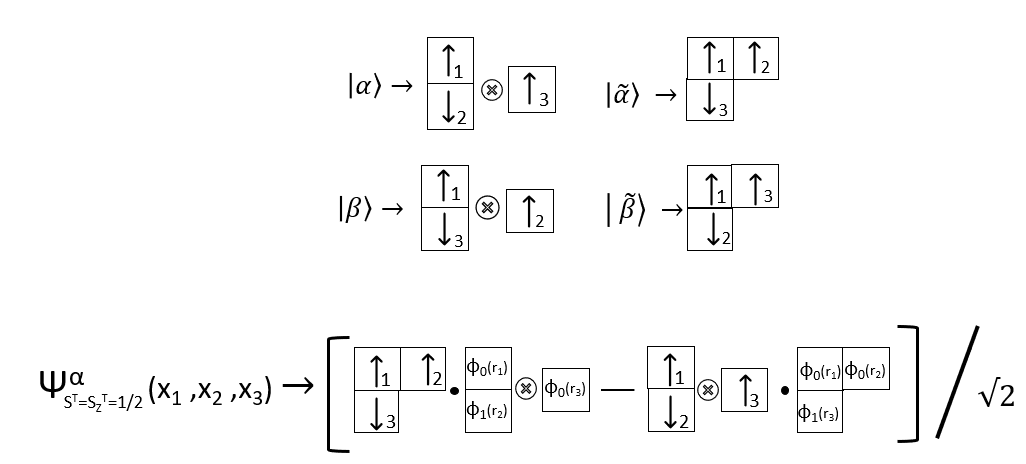

We can construct the same total 3-electron wavefunction instead by starting from spin states $|\beta\rangle$ and $|\tilde \beta\rangle$:


$$\Psi^{\beta}_{S^T=S^T_z=\frac{1}{2}}(x_1,x_2,x_3)=\Big( |\tilde \beta\rangle \Phi_{A_{13}} (x_1,x_2,x_3)  -|\beta\rangle \Phi_{S_{13}} (x_1,x_2,x_3)  \Big) /\sqrt{2}\\  \quad \quad \quad \quad \quad \quad\quad\quad=  - \frac{1}{\sqrt{3!}} \left| \begin{array}{ccc}
 |\uparrow_1\rangle \phi_0(x_1)   & |\uparrow_2\rangle \phi_0(x_2) & |\uparrow_3\rangle \phi_0(x_3)\\
 |\downarrow_1\rangle \phi_0(x_1)   & |\downarrow_2\rangle \phi_0(x_2) & |\downarrow_3\rangle \phi_0(x_3)\\
 |\uparrow_1\rangle \phi_1(x_1)   & |\uparrow_2\rangle \phi_1(x_2) & |\uparrow_3\rangle \phi_1(x_3)\\
\end{array} \right|=-\Psi^{\alpha}_{S^T=S^T_z=\frac{1}{2}}(x_1,x_2,x_3).$$


Important observation: to construct three-electron eigenstate (that satisfies Pauli principle) with $S^T=1/2$, corresponding energy level in Eq. (***) must be (at least doubly) degenerate, so that Schrodinger equation governing the coordinate part of wavefunction should allow solutions with two orthogonal states $\Phi_S$ and $\Phi_A$. As we outlined above (and in accordance with Wigner's result Eq. (11a) for $N_e=3$ and $S^T=1/2$ ) for 3 electrons one can construct 4 linearly independent spin states belonging to $S^T=1/2$ manifold (two with $M=1/2$ and two with $M=-1/2$). In the ground state configuration of 3-electron system these four spin states when combined with their corresponding coordinate parts give rise to only 2 distinct total 3-electron wavefunctions, one with $M=1/2$ (given in Eq. (12)) and another with $M=-1/2$ (obtained by reversing up-spin state into down-spin state in either the first or the last row of the matrix in Eq. (12)). For Lithium atom (with 3 electrons), in single-orbital picture, the ground state is approximated as $1s^22s^1$ state (two electrons occupy the lowest energy $1s$-orbital and the third one occupies $2s$-orbital). $1s^22s^1$ state can not have $S^T=3/2$ (because two electrons in $1s$ state must necessarily form spin-siglet, due to Pauli principle) and hence $1s^22s^1$ state must have $S^T=1/2$ and thus two-fold spin degeneracy $M=\pm 1/2$ (just like hydrgen atom's and other alkali-metal atoms spin degeneracy with 1 electron in the outer $s$-shell). The ground state with $M=1/2$ is obtained from the determinant of a matrix in the right-hand-side of Eq. (12), by substituting $\phi_0(x_j) \to \phi_{1s}(\vec r_j)$, $\phi_1(x_j) \to \phi_{2s}(\vec r_j)$. To approximate the Lithium atom ground state with $M=-1/2$, we have to reverse up-spin state into down-spin state in either the first or the last row of the matrix in Eq. (12).

All these that we have presented so far is well described in textbooks, for example see [4], where a general mathematical scheme can be found for constructing many-body states for identical particles based on irreducible representations of symmetric (permutation) group and associated with them Young tableaux developed by Wigner.

### Truly many-body case: Three-electron coordinate wavefunction not separable into product of single electron orbitals 

Below we will study the case when three-electron coordinate wavefunction is not separable into the product of single-particle orbitals. This case holds generically, when electrons interact with each other and total Hamiltonian describing the many-body system is not a direct sum of Hamiltonians describing individual electron. However, since electrons are indistinguishable partilces, Hamiltonian is still *invariant* under all permutations of the *spatial* variables, just like total spin operator and its $z$ projection are invariant with respect to all permutations of individual spin operators. 

We introduce 1D segment of length $L$ and discretize it with $N$ points to perform numerical simulation of Eq. (***). Interaction between electrons is assumed to be short-ranged with a radius $r_0$:  inter-electron interactions are modeled by repulsive "soft-core" potential $U(x_i-x_j) \sim \Theta(r_0-|x_i-x_j|)$, with a Heaviside function $\Theta$. At the boundaries of 1D segment ($x=0$ and $x=L$) we intorduce a high potential ($V_{boundary}$), to force vanishing of the wavefunction there (mimicking infinite walls).

L = 2;  % 1D segment Length 
N =12;  % Number of coordinate points
h_bar=1;
m=1;
r0=0.1;
x = linspace(0, L, N).'; % Coordinate column vector in x direction
dx = x(2) - x(1); % Coordinate step 
 
e    = ones(N,1);  % a column of 1-s with N elements       
Lap_1D  = spdiags([e -2*e e],[-1 0 1],N,N) / dx^2;  % sparse NxN matrix with -2*e along the main diagonal
% % and vector e along upper and lower diagonals, so called 3-point Laplacian

Lap_1=kron(kron(Lap_1D,speye(N)),speye(N));  % Laplacian of first particle
Lap_2=kron(kron(speye(N),Lap_1D),speye(N));  % Laplacian of second particle
Lap_3=kron(kron(speye(N),speye(N)),Lap_1D);  % Laplacian of third particle 
V_boundary=sparse(kron(kron(heaviside(x-L)+heaviside(0-x),e),e)+kron(kron(e,heaviside(x-L)+heaviside(0-x)),e)+kron(e,kron(e,heaviside(x-L)+heaviside(0-x))));
% V_boundary creates high potential at the boundary of the region, forcing wavefunction to vanish there

V_boundary=100*spdiags(V_boundary,0,N^3,N^3);
[X,Y,Z]=meshgrid(x);  % X,Y,Z are 3D tensors of size [N,N,N] encoding 3D coordinate grid
% X encodes coordinates of first particles, Y - of second and Z - of third 
U=heaviside(r0^2-(X-Y).^2)+heaviside(r0^2-(X-Z).^2)+heaviside(r0^2-(Z-Y).^2);   % U is three dimensional tensor here with size(U)= [N,N,N]
U=spdiags(U(:),0, N^3,N^3);   % U becomes sparse diagonal matrix of linear dimension N^3 


H=-h_bar^2/(2*m)*(Lap_1+Lap_2+Lap_3)+5*U+V_boundary;          % matrix corresponding to the total dimensionless hamiltonian Eq. (*) 

[V,E] = eigs(H,14,'smallestreal'); % find eigenvalues and eigenfunctions of H, 15 smallest
[E,ind] = sort(diag(E));       % convert diagonal matrix E to a column vector and sort low to high
V = V(:,ind);                  % rearrange corresponding eigenvectors. 

E % show energies 

E =     5.0878
    7.7005
    7.7005
    8.8056
   10.9779
   10.9779
   12.1290
   12.9671
   12.9671
   14.1864


[X2,Y2]=meshgrid(x); % 2D meshgrid for crating convenient surface plots below

V0=reshape(V(:,1),N,N,N);  % the lowest energy state, non-degenerate state, 
% fully symmetric, hence not applicable for 3-electron system
% we are reshaping V(:,1) column into 3D tensor to analyse syetry
% properties with respect of exchanging any two pair of coordinates
surf(X2,Y2,reshape(V0(:,:,N/2),N,N)) % visually check symmetry of the ground state with respect to exchaning x1 and x2 for x3=L
xlabel('x1')
ylabel('x2')
zlabel('The lowest energy fully symmetric state')
surf(X2,Y2,reshape(V0(:,N/2,:),N,N)) % visually check symmetry of the ground state with respect to exchaning x1 and x3 for x2=L
xlabel('x1')
ylabel('x3')
zlabel('The lowest energy fully symmetric state')
surf(X2,Y2,reshape(V0(N/2,:,:),N,N)) % visually check symmetry of the ground state with respect to exchaning x2 and x3 for x1=L
xlabel('x2')
ylabel('x3')
zlabel('The lowest energy fully symmetric state')
V11=reshape(V(:,11),N,N,N); % 11-th excited, non-degenerate state, fully antisymmetric state
surf(X2,Y2,reshape(V11(:,:,N/2),N,N))  % visually check antisymmetry of this state with respect to exchaning x1 and x2
xlabel('x1')
ylabel('x2')
zlabel('V11, fully antisymmetric state')
V11(:,:,N/2)    % confirm antisymmetry of this state with respect to exchaning x1 and x2, here x3=L

ans =     0.0003    0.0015    0.0026    0.0033    0.0032    0.0024    0.0012   -0.0005   -0.0019   -0.0025   -0.0019   -0.0004
    0.0015    0.0075    0.0131    0.0163    0.0162    0.0122    0.0060   -0.0027   -0.0100   -0.0126   -0.0095   -0.0020
    0.0026    0.0131    0.0197    0.0249    0.0246    0.0183    0.0085   -0.0051   -0.0164   -0.0204   -0.0152   -0.0031
    0.0033    0.0163    0.0249    0.0268    0.0265    0.0192    0.0080   -0.0073   -0.0200   -0.0242   -0.0178   -0.0037
    0.0032    0.0162    0.0246    0.0265    0.0219    0.0153    0.0051   -0.0085   -0.0196   -0.0230   -0.0168   -0.0034
    0.0024    0.0122    0.0183    0.0192    0.0153    0.0084    0.0015   -0.0076   -0.0150   -0.0169   -0.0122   -0.0025
    0.0012    0.0060    0.0085    0.0080    0.0051    0.0015   -0.0015   -0.0051   -0.0080   -0.0085   -0.0060   -0.0012
   -0.0005   -0.0027   -0.0051   -0.0073   -0.0085   -0.0076   -0.0051   -0.0018    0.0005    0.0016    0.0015    0.0003
   -0.0019   -0.0100   -0.

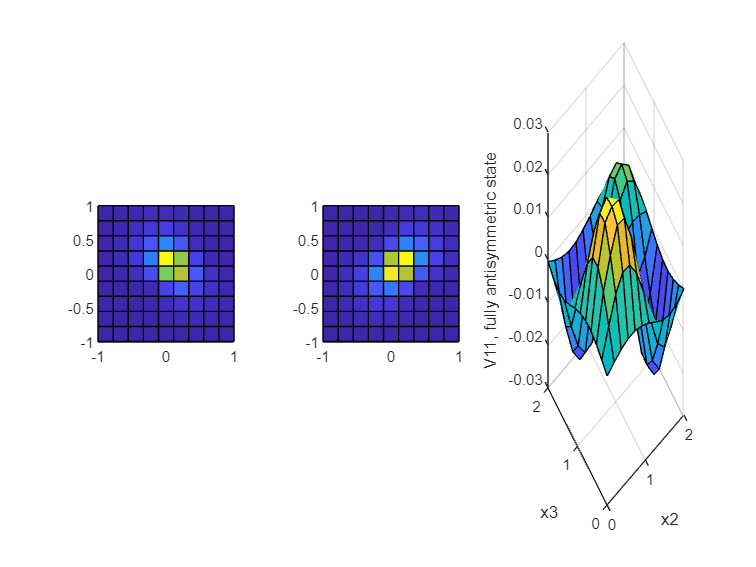

surf(X2,Y2,reshape(V11(:,N/2,:),N,N)) % visually check antisymmetry of this state with respect to exchaning x1 and x3 for x2=L
xlabel('x1')
ylabel('x3')
zlabel('V11, fully antisymmetric state')
surf(X2,Y2,reshape(V11(N/2,:,:),N,N)) % visually check antisymmetry of this state with respect to exchaning x2 and x3 for x1=L
xlabel('x2')
ylabel('x3')
zlabel('V11, fully antisymmetric state')

V1=reshape(V(:,2),N,N,N); % the first lowest excited state
reshape(V1(:,:,N/2),N,N)  % check that there is no symmetry or antisymmetry n this state with respect to exchanging x1 and x2 for x3=L

ans =     0.0001    0.0006    0.0005   -0.0003   -0.0018   -0.0037   -0.0061   -0.0078   -0.0083   -0.0071   -0.0045   -0.0009
    0.0007    0.0032    0.0032   -0.0007   -0.0084   -0.0182   -0.0306   -0.0397   -0.0422   -0.0365   -0.0231   -0.0045
    0.0017    0.0078    0.0082    0.0026   -0.0100   -0.0264   -0.0471   -0.0626   -0.0675   -0.0588   -0.0373   -0.0073
    0.0030    0.0143    0.0180    0.0109   -0.0043   -0.0255   -0.0517   -0.0720   -0.0795   -0.0701   -0.0448   -0.0088
    0.0045    0.0218    0.0300    0.0252    0.0080   -0.0156   -0.0439   -0.0671   -0.0771   -0.0695   -0.0449   -0.0089
    0.0057    0.0283    0.0412    0.0397    0.0243    0.0000   -0.0273   -0.0510   -0.0631   -0.0589   -0.0387   -0.0077
    0.0075    0.0375    0.0562    0.0582    0.0436    0.0175   -0.0098   -0.0359   -0.0514   -0.0509   -0.0343   -0.0069
    0.0085    0.0430    0.0656    0.0709    0.0582    0.0327    0.0071   -0.0168   -0.0344   -0.0378   -0.0266   -0.0054
    0.0084    0.0425    0.

V2=reshape(V(:,3),N,N,N);  % the second lowest excited state, degenerate in energy with the first one
reshape(V2(:,:,N/2),N,N)   % check that there is no symmetry or antisymmetry n this state with respect to exchanging x1 and x2 for x3=L

ans =     0.0003    0.0017    0.0031    0.0042    0.0047    0.0045    0.0044    0.0040    0.0033    0.0024    0.0014    0.0003
    0.0017    0.0085    0.0154    0.0208    0.0234    0.0222    0.0220    0.0199    0.0165    0.0119    0.0068    0.0013
    0.0027    0.0137    0.0218    0.0301    0.0341    0.0323    0.0315    0.0282    0.0230    0.0165    0.0093    0.0018
    0.0030    0.0151    0.0243    0.0288    0.0332    0.0311    0.0295    0.0255    0.0200    0.0139    0.0076    0.0014
    0.0023    0.0119    0.0189    0.0220    0.0211    0.0191    0.0161    0.0120    0.0077    0.0043    0.0019    0.0003
    0.0009    0.0046    0.0067    0.0065    0.0040   -0.0000   -0.0045   -0.0083   -0.0103   -0.0096   -0.0063   -0.0013
   -0.0007   -0.0038   -0.0076   -0.0121   -0.0170   -0.0214   -0.0258   -0.0300   -0.0300   -0.0250   -0.0155   -0.0030
   -0.0021   -0.0113   -0.0203   -0.0286   -0.0355   -0.0400   -0.0462   -0.0444   -0.0432   -0.0355   -0.0218   -0.0043
   -0.0030   -0.0156   -0.

The lowest energy state is a unique (energetically non-degenerate state) and fully symmetric with respect to exchanging any 2 coordinates of 3 particles, hence it can not describe system of 3 electrons. There are a few other fully symmetric states (e.g. fourth in energy $V(:,4)$ and seventh in energy $V(:,7)$states), which are also unique, non-degenerate in energy. These states must be ignored when studying systems of electrons. 12-th in energy state, vector $V(:,12)$ is also a unique non-degenerate eigenvector, however it is a fully antisymmetric with respect to exchanging any pair of coordinates of 3 particles. Hence it should be coupled with $S^T=3/2$ quadruplet (ferromagnetic multiplet), any of the states of the quadruplet being a fully symmetric state in spin variables.

Fully symmetric and fully antisymmetric coordinate wavefunctions (with respect to exchanging any pair of coordinates) are the only generically non-degenerate solutions of the Schrodinger equation (there is no reason for their degeneracy), whereas any other wavefunction must necessarily be a member of at least two-fold degenerate solutions.

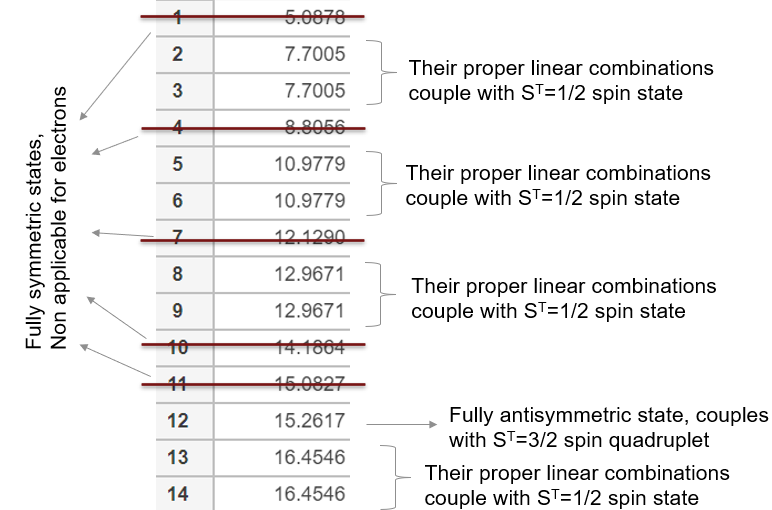

First excited state as we see is doubly degenerate. Wavefunctions $V1=V(:,2)$ and $V2=V(:,3)$, as returned by computer, do not show any apparent symmetry with respect to exchanging any pair of coordinates. 

From linear combinations of two degenerate vectors $V1$ and $V2$ we construnct coordinate wavefunctions $V_{S_{12}}$/ $V_{A_{12}}$ that are symetric/ antisymmetric with respect to exchanging coordinates of 1-st and 2-nd particles. The fact that this is possible is guaranteed by symmetries of the solutions of the differential equations (here reduced to matrix eugenvalue problems), such as Eq. (***), that are invariant with respect to permutations of particles' coordinates.

For this, we search for appropriate real number, angle of admixture between $V1$ and $V2$, $u_{12}$. This number is non-universal, depends on all details of the model studied, including $L$, $N$, interaction strength, etc.

u_12=0.3783514434919;
V_S12=-V1-u_12*V2;
V_A12=u_12*V1-V2;

reshape(V_S12(:,:,N/2),N,N)   % symmetric matrix (with respect to exchanging x1 and x2) for any value of x3, here x3=L

ans =    -0.0002   -0.0012   -0.0017   -0.0013    0.0000    0.0020    0.0044    0.0063    0.0070    0.0062    0.0040    0.0008
   -0.0014   -0.0064   -0.0091   -0.0072   -0.0004    0.0098    0.0223    0.0322    0.0360    0.0320    0.0205    0.0041
   -0.0027   -0.0130   -0.0165   -0.0140   -0.0029    0.0142    0.0352    0.0520    0.0588    0.0525    0.0338    0.0067
   -0.0041   -0.0200   -0.0272   -0.0218   -0.0083    0.0137    0.0405    0.0624    0.0719    0.0649    0.0419    0.0083
   -0.0053   -0.0263   -0.0372   -0.0335   -0.0159    0.0084    0.0378    0.0626    0.0742    0.0679    0.0442    0.0088
   -0.0061   -0.0301   -0.0437   -0.0422   -0.0258   -0.0000    0.0289    0.0541    0.0670    0.0626    0.0411    0.0082
   -0.0072   -0.0361   -0.0533   -0.0537   -0.0371   -0.0094    0.0195    0.0472    0.0627    0.0603    0.0402    0.0080
   -0.0077   -0.0387   -0.0580   -0.0600   -0.0448   -0.0176    0.0104    0.0336    0.0507    0.0512    0.0349    0.0070
   -0.0073   -0.0366   -0.

reshape(V_S12(:,:,N/2),N,N) -reshape(V_S12(:,:,N/2),N,N).' % matrix minus it's transpose

ans =          0    0.0001    0.0010    0.0028    0.0053    0.0080    0.0116    0.0140    0.0143    0.0121    0.0075    0.0015
   -0.0001         0    0.0039    0.0128    0.0259    0.0398    0.0583    0.0708    0.0726    0.0615    0.0384    0.0075
   -0.0010   -0.0039         0    0.0132    0.0343    0.0579    0.0885    0.1099    0.1142    0.0975    0.0612    0.0120
   -0.0028   -0.0128   -0.0132         0    0.0253    0.0559    0.0942    0.1224    0.1305    0.1130    0.0715    0.0141
   -0.0053   -0.0259   -0.0343   -0.0253         0    0.0342    0.0750    0.1074    0.1200    0.1067    0.0684    0.0135
   -0.0080   -0.0398   -0.0579   -0.0559   -0.0342         0    0.0383    0.0717    0.0887    0.0829    0.0544    0.0108
   -0.0116   -0.0583   -0.0885   -0.0942   -0.0750   -0.0383         0    0.0368    0.0600    0.0621    0.0427    0.0086
   -0.0140   -0.0708   -0.1099   -0.1224   -0.1074   -0.0717   -0.0368         0    0.0270    0.0365    0.0275    0.0057
   -0.0143   -0.0726   -0.

reshape(V_A12(:,:,N/2),N,N)   % antisymmetric matrix for any value of x3, here x3=L

ans =    -0.0003   -0.0015   -0.0029   -0.0043   -0.0054   -0.0059   -0.0067   -0.0070   -0.0065   -0.0051   -0.0031   -0.0006
   -0.0014   -0.0073   -0.0142   -0.0211   -0.0265   -0.0291   -0.0336   -0.0350   -0.0324   -0.0258   -0.0155   -0.0030
   -0.0021   -0.0108   -0.0187   -0.0291   -0.0378   -0.0423   -0.0494   -0.0519   -0.0485   -0.0387   -0.0234   -0.0045
   -0.0018   -0.0097   -0.0175   -0.0247   -0.0348   -0.0408   -0.0490   -0.0527   -0.0501   -0.0404   -0.0246   -0.0048
   -0.0007   -0.0037   -0.0076   -0.0125   -0.0181   -0.0249   -0.0327   -0.0373   -0.0369   -0.0306   -0.0189   -0.0037
    0.0012    0.0061    0.0089    0.0085    0.0052    0.0000   -0.0059   -0.0110   -0.0136   -0.0127   -0.0083   -0.0017
    0.0035    0.0180    0.0288    0.0341    0.0335    0.0280    0.0221    0.0164    0.0106    0.0058    0.0025    0.0004
    0.0054    0.0276    0.0451    0.0554    0.0575    0.0524    0.0489    0.0380    0.0302    0.0212    0.0117    0.0022
    0.0062    0.0317    0.

reshape(V_A12(:,:,N/2),N,N) +reshape(V_A12(:,:,N/2),N,N).' % matrix plus it's transpose

ans =    -0.0006   -0.0029   -0.0050   -0.0061   -0.0060   -0.0046   -0.0032   -0.0016   -0.0003    0.0004    0.0005    0.0001
   -0.0029   -0.0145   -0.0250   -0.0308   -0.0302   -0.0230   -0.0156   -0.0074   -0.0007    0.0028    0.0029    0.0006
   -0.0050   -0.0250   -0.0373   -0.0466   -0.0454   -0.0334   -0.0206   -0.0068    0.0038    0.0086    0.0072    0.0015
   -0.0061   -0.0308   -0.0466   -0.0493   -0.0473   -0.0322   -0.0149    0.0027    0.0151    0.0190    0.0140    0.0029
   -0.0060   -0.0302   -0.0454   -0.0473   -0.0361   -0.0197    0.0008    0.0201    0.0321    0.0330    0.0226    0.0046
   -0.0046   -0.0230   -0.0334   -0.0322   -0.0197    0.0000    0.0221    0.0414    0.0512    0.0478    0.0314    0.0063
   -0.0032   -0.0156   -0.0206   -0.0149    0.0008    0.0221    0.0443    0.0653    0.0741    0.0664    0.0427    0.0085
   -0.0016   -0.0074   -0.0068    0.0027    0.0201    0.0414    0.0653    0.0761    0.0843    0.0746    0.0478    0.0094
   -0.0003   -0.0007    0.

Functions $V_{S_{12}}$/$V_{A_{12}}$ are three-body coordinate wavefunctions, symmetric/ antisymmetric with exchange $x_1 \leftrightarrow x_2$, degenerate in energy with (and orthogonal to) each other, solutions of Schrodinger equation Eq. (***), and highly unlikely to be separable into the direct product of single-particle wavefunctions. Let us construct with their help and with $|\alpha \rangle$and $|\tilde \alpha\rangle$a total 3-electron wavefunction as follows (in analogy to the prescription by Wigner discussed above)


$$(13)\quad \Psi^{\alpha}_{S^T=S^T_z=\frac{1}{2}}(x_1,x_2,x_3) =\frac{1}{\sqrt{12}} \Big(   |\uparrow_1\rangle \otimes |\downarrow_2 \rangle \otimes  |\uparrow_3\rangle + |\downarrow_1\rangle\otimes | \uparrow_2\rangle \otimes |\uparrow_3 \rangle  -2 |\uparrow_1\rangle \otimes |\uparrow_2\rangle \otimes |\downarrow_3 \rangle \Big) V_{A_{12}}(x_1,x_2,x_3)\\ 
\quad\quad\quad\quad\quad\quad\quad\quad  -\frac{1}{\sqrt{4}} \Big(  | \uparrow_1\rangle \otimes | \downarrow_2 \rangle \otimes | \uparrow_3\rangle - |\downarrow_1\rangle \otimes |\uparrow_2\rangle \otimes | \uparrow_3\rangle   \Big) V_{S_{12}} (x_1,x_2,x_3).$$


By construction $\Psi^{\alpha}_{S^T=S^T_z=\frac{1}{2}}(x_1,x_2,x_3)$ is explicitely symmetric with respect to exchanging first and second electrons, ($s_1 \leftrightarrow s_2$ and$x_1 \leftrightarrow x_2$). We need to check if antisymmetry holds for exchanging any two electrons.

Since total 3-electron wavefunction in Eq. (13) is not written in the form of a matrix determinant (as opposed to Eq. (12) where 3-body cordinate wavefunctions were represented by the products of single-electron orbitals) this check needs numerical confirmation.

Let's exchange 1-st and 3-rd electrons. Then, relations like below must be satisfied in order to have antisymmetry of the total wavefunction:

$\frac{2}{\sqrt{3}} V_{A_{12}}(x_1,x_2,x_3)-V_{S_{12}}(x_3,x_2,x_1) -\frac{1}{\sqrt{3}} V_{A_{12}}(x_3,x_2,x_1)=0$,

$-V_{S_{12}}(x_1,x_2,x_3) +\frac{1}{\sqrt{3}} V_{A_{12}}(x_1,x_2,x_3)=V_{S_{12}}(x_3,x_2,x_1) -\frac{1}{\sqrt{3}} V_{A_{12}}(x_3,x_2,x_1)$,

$V_{S_{12}}(x_1,x_2,x_3) +\frac{1}{\sqrt{3}} V_{A_{12}}(x_1,x_2,x_3)=-V_{S_{12}}(x_1,x_3,x_2) -\frac{1}{\sqrt{3}} V_{A_{12}}(x_1,x_3,x_2)$.

We check below numerically that indeed such equations are satisfied.

% here x2=L, these equations however hold for any value of x2
2/sqrt(3)*reshape(V_A12(:,N/2,:),N,N)-reshape(V_S12(:,N/2,:),N,N).'-1/sqrt(3)*reshape(V_A12(:,N/2,:),N,N).' 

ans =    -0.0004   -0.0023   -0.0049   -0.0080   -0.0112   -0.0135   -0.0170   -0.0189   -0.0183   -0.0150   -0.0092   -0.0018
   -0.0020   -0.0106   -0.0231   -0.0388   -0.0548   -0.0672   -0.0852   -0.0950   -0.0924   -0.0758   -0.0465   -0.0091
   -0.0024   -0.0133   -0.0272   -0.0508   -0.0765   -0.0976   -0.1270   -0.1440   -0.1417   -0.1170   -0.0721   -0.0141
   -0.0010   -0.0063   -0.0173   -0.0360   -0.0666   -0.0942   -0.1300   -0.1529   -0.1540   -0.1291   -0.0802   -0.0157
    0.0024    0.0107    0.0102   -0.0026   -0.0264   -0.0576   -0.0942   -0.1211   -0.1284   -0.1108   -0.0700   -0.0138
    0.0068    0.0336    0.0488    0.0471    0.0288    0.0000   -0.0323   -0.0605   -0.0748   -0.0699   -0.0459   -0.0091
    0.0124    0.0624    0.0970    0.1082    0.0954    0.0646    0.0323    0.0011   -0.0218   -0.0300   -0.0227   -0.0047
    0.0165    0.0842    0.1341    0.1568    0.1505    0.1209    0.0942    0.0555    0.0274    0.0083    0.0001   -0.0003
    0.0179    0.0914    0.

% zero within 10^(-14) accuracy, depending on precise value of u_12
reshape(-V_S12(:,N/2,:),N,N)+1/sqrt(3)*reshape(V_A12(:,N/2,:),N,N)  % antisymmetric matrix (with respect to exchanging x1 and x3) for any fixed x2, here x2=L

ans =    -0.0004   -0.0022   -0.0039   -0.0052   -0.0057   -0.0054   -0.0052   -0.0046   -0.0037   -0.0027   -0.0015   -0.0003
   -0.0021   -0.0106   -0.0192   -0.0257   -0.0284   -0.0266   -0.0257   -0.0227   -0.0183   -0.0130   -0.0073   -0.0014
   -0.0034   -0.0173   -0.0272   -0.0373   -0.0416   -0.0386   -0.0367   -0.0319   -0.0252   -0.0176   -0.0097   -0.0018
   -0.0038   -0.0194   -0.0308   -0.0360   -0.0408   -0.0372   -0.0340   -0.0281   -0.0210   -0.0138   -0.0073   -0.0014
   -0.0031   -0.0157   -0.0247   -0.0284   -0.0264   -0.0228   -0.0178   -0.0116   -0.0059   -0.0020   -0.0002    0.0000
   -0.0014   -0.0070   -0.0102   -0.0099   -0.0060    0.0000    0.0068    0.0127    0.0157    0.0146    0.0096    0.0019
    0.0005    0.0029    0.0067    0.0122    0.0189    0.0256    0.0323    0.0387    0.0394    0.0333    0.0208    0.0041
    0.0022    0.0120    0.0220    0.0319    0.0410    0.0478    0.0567    0.0555    0.0549    0.0456    0.0281    0.0055
    0.0033    0.0173    0.

reshape(V_S12(N/2,:,:),N,N)+1/sqrt(3)*reshape(V_A12(N/2,:,:),N,N)  % antisymmetric matrix (with respect to exchanging x2 and x3) for any fixed x1, here x1=L 

ans =     0.0001    0.0003    0.0000   -0.0012   -0.0031   -0.0054   -0.0083   -0.0103   -0.0108   -0.0092   -0.0058   -0.0011
    0.0006    0.0022    0.0009   -0.0050   -0.0149   -0.0266   -0.0417   -0.0523   -0.0547   -0.0469   -0.0295   -0.0058
    0.0015    0.0067    0.0057   -0.0029   -0.0190   -0.0386   -0.0637   -0.0819   -0.0868   -0.0749   -0.0473   -0.0093
    0.0030    0.0144    0.0171    0.0075   -0.0119   -0.0372   -0.0688   -0.0928   -0.1008   -0.0882   -0.0561   -0.0111
    0.0050    0.0242    0.0328    0.0263    0.0055   -0.0228   -0.0567   -0.0841   -0.0955   -0.0856   -0.0551   -0.0109
    0.0068    0.0336    0.0488    0.0471    0.0288   -0.0000   -0.0323   -0.0605   -0.0748   -0.0699   -0.0459   -0.0091
    0.0093    0.0464    0.0700    0.0734    0.0565    0.0256   -0.0068   -0.0378   -0.0566   -0.0570   -0.0387   -0.0078
    0.0108    0.0546    0.0840    0.0920    0.0780    0.0478    0.0178   -0.0116   -0.0333   -0.0390   -0.0281   -0.0057
    0.0109    0.0549    0.

Analogically, we can construnct coordinate wavefunctions $V_{S_{13}}$/$V_{A_{13}}$ that are symmetric/ antisymmetric with respect to exchanging coordinates of 1-st and 3-rd particles and are linear combination between $V1$ and $V2$. Again we search for appropriate real number, which we denote as $u_{13}$. Total (accounting for both spins and coordinates) 3-electron wavefunction represented with $|\beta\rangle$ and $|\tilde \beta \rangle$ will look:

$\Psi^{\beta}_{S^T=S^T_z=\frac{1}{2}}(x_1,x_2,x_3)=|\tilde \beta\rangle V_{A_{13}} (x_1,x_2,x_3)/\sqrt{2} -|\beta\rangle V_{S_{13}} (x_1,x_2,x_3)/\sqrt{2} =-\Psi^{\alpha}_{S^T=S^T_z=\frac{1}{2}}(x_1,x_2,x_3)$.

For the last equality (showing that $\Psi^{\beta}=-\Psi^{\alpha}$, hence both total 3-electron states describe the same wavefunction) we have used the following relations that we checked numerically to hold for any values of $x_j$:

$V_{S_{12}}(x_1,x_2,x_3)+V_{A_{12}}(x_1,x_2,x_3)/\sqrt{3}+V_{S_{13}}(x_1,x_2,x_3)+V_{A_{13}}(x_1,x_2,x_3)/\sqrt{3}=0$,

$-V_{S_{12}}(x_1,x_2,x_3)/2+V_{A_{12}}(x_1,x_2,x_3)/\sqrt{12}-V_{A_{13}}(x_1,x_2,x_3)/\sqrt{3}=0$,

$V_{A_{12}}(x_1,x_2,x_3)/\sqrt{3}+V_{S_{13}}(x_1,x_2,x_3)/2-V_{A_{13}}(x_1,x_2,x_3)/\sqrt{12}=0$.

u_13=6.122856773029

u_13 = 6.1229


V_S13=V1+u_13*V2;
V_A13=u_13*V1-V2;

reshape(V_S13(:,N/2,:),N,N)   % symmetric matrix (with respect to exchanging x1 and x3) for any value of x2, here x2=L

ans =    -0.0007   -0.0031   -0.0025    0.0027    0.0122    0.0238    0.0387    0.0494    0.0522    0.0449    0.0283    0.0056
   -0.0041   -0.0179   -0.0165    0.0092    0.0578    0.1179    0.1949    0.2508    0.2657    0.2292    0.1446    0.0284
   -0.0098   -0.0450   -0.0459   -0.0089    0.0700    0.1713    0.2995    0.3950    0.4238    0.3683    0.2333    0.0459
   -0.0178   -0.0851   -0.1059   -0.0608    0.0345    0.1652    0.3272    0.4526    0.4974    0.4380    0.2795    0.0551
   -0.0270   -0.1323   -0.1818   -0.1511   -0.0445    0.1011    0.2760    0.4188    0.4801    0.4321    0.2788    0.0552
   -0.0352   -0.1745   -0.2536   -0.2447   -0.1497   -0.0000    0.1679    0.3140    0.3887    0.3630    0.2384    0.0474
   -0.0466   -0.2333   -0.3502   -0.3639   -0.2741   -0.1134    0.0545    0.2155    0.3114    0.3095    0.2092    0.0420
   -0.0534   -0.2690   -0.4118   -0.4460   -0.3692   -0.2121   -0.0546    0.0937    0.2028    0.2259    0.1599    0.0325
   -0.0529   -0.2674   -0.

reshape(V_S13(:,N/2,:),N,N)-reshape(V_S13(:,N/2,:),N,N).'

ans =          0    0.0011    0.0073    0.0205    0.0392    0.0589    0.0853    0.1029    0.1051    0.0888    0.0554    0.0109
   -0.0011         0    0.0285    0.0943    0.1901    0.2924    0.4282    0.5198    0.5331    0.4515    0.2821    0.0553
   -0.0073   -0.0285         0    0.0971    0.2518    0.4249    0.6497    0.8067    0.8383    0.7155    0.4489    0.0881
   -0.0205   -0.0943   -0.0971         0    0.1856    0.4099    0.6910    0.8986    0.9577    0.8294    0.5245    0.1032
   -0.0392   -0.1901   -0.2518   -0.1856         0    0.2507    0.5501    0.7881    0.8810    0.7830    0.5019    0.0992
   -0.0589   -0.2924   -0.4249   -0.4099   -0.2507         0    0.2813    0.5262    0.6513    0.6081    0.3995    0.0795
   -0.0853   -0.4282   -0.6497   -0.6910   -0.5501   -0.2813         0    0.2701    0.4402    0.4555    0.3131    0.0631
   -0.1029   -0.5198   -0.8067   -0.8986   -0.7881   -0.5262   -0.2701         0    0.1980    0.2680    0.2021    0.0417
   -0.1051   -0.5331   -0.

reshape(V_A13(:,N/2,:),N,N)   % antisymmetric matrix for any value of x2, here x2=L

ans =    -0.0021   -0.0110   -0.0195   -0.0260   -0.0287   -0.0269   -0.0261   -0.0232   -0.0188   -0.0134   -0.0075   -0.0014
   -0.0106   -0.0532   -0.0963   -0.1289   -0.1428   -0.1335   -0.1290   -0.1142   -0.0921   -0.0654   -0.0366   -0.0069
   -0.0171   -0.0868   -0.1369   -0.1873   -0.2088   -0.1940   -0.1844   -0.1603   -0.1268   -0.0885   -0.0488   -0.0092
   -0.0191   -0.0973   -0.1548   -0.1810   -0.2048   -0.1871   -0.1706   -0.1410   -0.1054   -0.0696   -0.0367   -0.0068
   -0.0156   -0.0790   -0.1243   -0.1426   -0.1325   -0.1145   -0.0894   -0.0583   -0.0299   -0.0103   -0.0013    0.0001
   -0.0071   -0.0353   -0.0514   -0.0495   -0.0303    0.0000    0.0340    0.0636    0.0787    0.0735    0.0483    0.0096
    0.0025    0.0147    0.0336    0.0613    0.0952    0.1284    0.1624    0.1943    0.1980    0.1672    0.1043    0.0204
    0.0113    0.0602    0.1104    0.1605    0.2061    0.2402    0.2850    0.2791    0.2761    0.2289    0.1414    0.0276
    0.0165    0.0868    0.

reshape(V_A13(:,N/2,:),N,N)+reshape(V_A13(:,N/2,:),N,N).'

ans =    -0.0041   -0.0216   -0.0366   -0.0451   -0.0443   -0.0340   -0.0236   -0.0120   -0.0024    0.0029    0.0035    0.0008
   -0.0216   -0.1064   -0.1831   -0.2262   -0.2218   -0.1688   -0.1143   -0.0540   -0.0052    0.0207    0.0215    0.0047
   -0.0366   -0.1831   -0.2738   -0.3421   -0.3332   -0.2453   -0.1508   -0.0499    0.0278    0.0631    0.0530    0.0112
   -0.0451   -0.2262   -0.3421   -0.3621   -0.3474   -0.2367   -0.1094    0.0195    0.1106    0.1391    0.1025    0.0210
   -0.0443   -0.2218   -0.3332   -0.3474   -0.2650   -0.1448    0.0057    0.1478    0.2359    0.2422    0.1659    0.0334
   -0.0340   -0.1688   -0.2453   -0.2367   -0.1448    0.0000    0.1624    0.3038    0.3760    0.3511    0.2306    0.0459
   -0.0236   -0.1143   -0.1508   -0.1094    0.0057    0.1624    0.3248    0.4793    0.5438    0.4872    0.3137    0.0621
   -0.0120   -0.0540   -0.0499    0.0195    0.1478    0.3038    0.4793    0.5583    0.6187    0.5478    0.3505    0.0692
   -0.0024   -0.0052    0.

2/sqrt(3)*reshape(V_A13(N/2,:,:),N,N)+reshape(V_S13(N/2,:,:),N,N).'-1/sqrt(3)*reshape(V_A13(N/2,:,:),N,N).' 

ans =    -0.0005   -0.0024   -0.0029   -0.0012    0.0029    0.0082    0.0150    0.0201    0.0217    0.0189    0.0120    0.0024
   -0.0028   -0.0129   -0.0162   -0.0076    0.0130    0.0408    0.0758    0.1023    0.1110    0.0970    0.0617    0.0122
   -0.0060   -0.0281   -0.0331   -0.0210    0.0124    0.0593    0.1178    0.1629    0.1789    0.1574    0.1004    0.0198
   -0.0097   -0.0471   -0.0617   -0.0438   -0.0031    0.0572    0.1315    0.1905    0.2139    0.1905    0.1222    0.0242
   -0.0136   -0.0666   -0.0930   -0.0808   -0.0320    0.0350    0.1159    0.1829    0.2130    0.1932    0.1251    0.0248
   -0.0165   -0.0816   -0.1186   -0.1144   -0.0700    0.0000    0.0785    0.1469    0.1818    0.1698    0.1115    0.0222
   -0.0207   -0.1035   -0.1543   -0.1579   -0.1145   -0.0393    0.0393    0.1145    0.1579    0.1543    0.1035    0.0207
   -0.0230   -0.1154   -0.1749   -0.1858   -0.1471   -0.0734    0.0014    0.0675    0.1162    0.1223    0.0847    0.0171
   -0.0223   -0.1123   -0.

% zero within 10^(-9) accuracy, depending on precise value of u_13

Finally, the coordinate wavefunctions $V_{S_{23}}$/ $V_{A_{23}}$ that are symmetric/ antisymmetric with respect to exchanging coordinates of 2-nd and 3-rd electrons can be obtained as: $V_{S_{23}}=V_{S_{12}}/|V_{S_{12}}| +V_{S_{13}}/|V_{S_{13}}|$ and $V_{A_{23}}=V_{A_{12}} /|V_{A_{12}}|-V_{A_{13}}/|V_{A_{13}}|$.

V_S12(:)=V_S12(:)/sqrt(V_S12(:).'*V_S12(:)); % first normalize vectors to unity
V_A12(:)=V_A12(:)/sqrt(V_A12(:).'*V_A12(:));
V_S13(:)=V_S13(:)/sqrt(V_S13(:).'*V_S13(:));
V_A13(:)=V_A13(:)/sqrt(V_A13(:).'*V_A13(:));

V_S23=reshape(V_S13+V_S12,N,N,N); % reshape N^3 element column vector into 3D tensor for convenience
reshape(V_S23(N/2,:,:),N,N)-reshape(V_S23(N/2,:,:),N,N).' %check that V_S23 is symmetric with respect to exchaning x2 and x3 for x1=L. Same symmetry is retained for any value of x1

ans =          0   -0.0000   -0.0002   -0.0007   -0.0013   -0.0020   -0.0029   -0.0035   -0.0035   -0.0030   -0.0019   -0.0004
    0.0000         0   -0.0010   -0.0032   -0.0064   -0.0099   -0.0145   -0.0175   -0.0180   -0.0152   -0.0095   -0.0019
    0.0002    0.0010         0   -0.0033   -0.0085   -0.0143   -0.0219   -0.0272   -0.0283   -0.0241   -0.0151   -0.0030
    0.0007    0.0032    0.0033         0   -0.0063   -0.0138   -0.0233   -0.0303   -0.0323   -0.0280   -0.0177   -0.0035
    0.0013    0.0064    0.0085    0.0063         0   -0.0085   -0.0186   -0.0266   -0.0297   -0.0264   -0.0169   -0.0033
    0.0020    0.0099    0.0143    0.0138    0.0085         0   -0.0095   -0.0178   -0.0220   -0.0205   -0.0135   -0.0027
    0.0029    0.0145    0.0219    0.0233    0.0186    0.0095         0   -0.0091   -0.0149   -0.0154   -0.0106   -0.0021
    0.0035    0.0175    0.0272    0.0303    0.0266    0.0178    0.0091         0   -0.0067   -0.0090   -0.0068   -0.0014
    0.0035    0.0180    0.

V_A23=reshape(-V_A13+V_A12,N,N,N); 
reshape(V_A23(N/2,:,:),N,N)+reshape(V_A23(N/2,:,:),N,N).'  %check that V_A23 is antisymmetric with respect to exchaning x2 and x3, here for x1=L. Same antisymmetry is retained for any value of x1

ans =     0.0001    0.0007    0.0012    0.0015    0.0015    0.0011    0.0008    0.0004    0.0001   -0.0001   -0.0001   -0.0000
    0.0007    0.0036    0.0062    0.0076    0.0075    0.0057    0.0039    0.0018    0.0002   -0.0007   -0.0007   -0.0002
    0.0012    0.0062    0.0092    0.0115    0.0112    0.0083    0.0051    0.0017   -0.0009   -0.0021   -0.0018   -0.0004
    0.0015    0.0076    0.0115    0.0122    0.0117    0.0080    0.0037   -0.0007   -0.0037   -0.0047   -0.0035   -0.0007
    0.0015    0.0075    0.0112    0.0117    0.0089    0.0049   -0.0002   -0.0050   -0.0080   -0.0082   -0.0056   -0.0011
    0.0011    0.0057    0.0083    0.0080    0.0049   -0.0000   -0.0055   -0.0103   -0.0127   -0.0118   -0.0078   -0.0015
    0.0008    0.0039    0.0051    0.0037   -0.0002   -0.0055   -0.0110   -0.0162   -0.0184   -0.0164   -0.0106   -0.0021
    0.0004    0.0018    0.0017   -0.0007   -0.0050   -0.0103   -0.0162   -0.0188   -0.0209   -0.0185   -0.0118   -0.0023
    0.0001    0.0002   -0.

reshape(V_S12(:,:,N/2),N,N)-reshape(V_S13(:,N/2,:),N,N)

ans =    -0.0001   -0.0006   -0.0012   -0.0017   -0.0020   -0.0020   -0.0021   -0.0021   -0.0018   -0.0014   -0.0008   -0.0002
   -0.0006   -0.0031   -0.0058   -0.0082   -0.0097   -0.0099   -0.0106   -0.0104   -0.0091   -0.0070   -0.0041   -0.0008
   -0.0009   -0.0049   -0.0080   -0.0116   -0.0140   -0.0143   -0.0154   -0.0151   -0.0133   -0.0102   -0.0060   -0.0012
   -0.0010   -0.0050   -0.0084   -0.0106   -0.0133   -0.0138   -0.0149   -0.0146   -0.0129   -0.0099   -0.0059   -0.0011
   -0.0006   -0.0033   -0.0055   -0.0070   -0.0077   -0.0085   -0.0091   -0.0090   -0.0080   -0.0061   -0.0036   -0.0007
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.0007    0.0039    0.0066    0.0085    0.0095    0.0095    0.0095    0.0095    0.0085    0.0066    0.0039    0.0007
    0.0014    0.0072    0.0122    0.0157    0.0176    0.0178    0.0186    0.0163    0.0147    0.0115    0.0068    0.0013
    0.0017    0.0088    0.

reshape(V_A12(:,:,N/2),N,N)-reshape(V_A13(:,N/2,:),N,N)

ans =     0.0001    0.0003    0.0004    0.0002   -0.0004   -0.0011   -0.0021   -0.0028   -0.0030   -0.0026   -0.0017   -0.0003
    0.0004    0.0018    0.0023    0.0011   -0.0018   -0.0057   -0.0106   -0.0143   -0.0155   -0.0135   -0.0086   -0.0017
    0.0008    0.0039    0.0046    0.0029   -0.0017   -0.0083   -0.0164   -0.0227   -0.0250   -0.0220   -0.0140   -0.0028
    0.0014    0.0066    0.0086    0.0061    0.0004   -0.0080   -0.0184   -0.0266   -0.0299   -0.0266   -0.0171   -0.0034
    0.0019    0.0093    0.0130    0.0113    0.0045   -0.0049   -0.0162   -0.0255   -0.0297   -0.0270   -0.0175   -0.0035
    0.0023    0.0114    0.0166    0.0160    0.0098   -0.0000   -0.0110   -0.0205   -0.0254   -0.0237   -0.0156   -0.0031
    0.0029    0.0144    0.0215    0.0220    0.0160    0.0055   -0.0055   -0.0160   -0.0220   -0.0215   -0.0144   -0.0029
    0.0032    0.0161    0.0244    0.0259    0.0205    0.0103   -0.0002   -0.0094   -0.0162   -0.0171   -0.0118   -0.0024
    0.0031    0.0157    0.

reshape(V_A12(:,N/2,:),N,N)/sqrt(3)-reshape(-V_S13(:,N/2,:),N,N)/2-reshape(V_A13(:,N/2,:),N,N)/sqrt(12)

ans = 1.0e-15 *

   -0.0048   -0.0248   -0.0409   -0.0473   -0.0412   -0.0252   -0.0054    0.0121    0.0235    0.0262    0.0183    0.0037
   -0.0254   -0.1245   -0.2056   -0.2385   -0.2108   -0.1223   -0.0260    0.0703    0.1292    0.1422    0.0974    0.0194
   -0.0447   -0.2203   -0.3209   -0.3747   -0.3261   -0.1787   -0.0156    0.1483    0.2481    0.2559    0.1748    0.0356
   -0.0579   -0.2880   -0.4224   -0.4215   -0.3574   -0.1717    0.0451    0.2455    0.3799    0.3656    0.2524    0.0499
   -0.0618   -0.3057   -0.4519   -0.4528   -0.3070   -0.1032    0.1448    0.3734    0.5029    0.4850    0.3236    0.0641
   -0.0546   -0.2704   -0.3955   -0.3825   -0.2351    0.0000    0.2617    0.4901    0.6011    0.5673    0.3725    0.0732
   -0.0495   -0.2456   -0.3355   -0.2979   -0.1301    0.1180    0.3790    0.6245    0.7442    0.6878    0.4450    0.0887
   -0.0401   -0.1999   -0.2593   -0.2056   -0.0364    0.2238    0.4892    0.6523    0.7702    0.7095    0.4614    0.0911
   -0.0296   -0

reshape(-V_S12(:,N/2-3,:),N,N)/2+reshape(V_A12(:,N/2-3,:),N,N)/sqrt(12)-reshape(V_A13(:,N/2-3,:),N,N)/sqrt(3)

ans = 1.0e-15 *

   -0.0002   -0.0001    0.0035    0.0133    0.0288    0.0479    0.0658    0.0771    0.0778    0.0647    0.0401    0.0079
   -0.0014   -0.0033    0.0137    0.0616    0.1401    0.2374    0.3289    0.3879    0.3901    0.3276    0.2036    0.0398
   -0.0050   -0.0196   -0.0000    0.0679    0.1882    0.3430    0.4901    0.5872    0.6037    0.5083    0.3166    0.0620
   -0.0129   -0.0579   -0.0481    0.0286    0.1874    0.4007    0.6141    0.7615    0.7945    0.6713    0.4259    0.0833
   -0.0250   -0.1158   -0.1318   -0.0677    0.0919    0.3452    0.6072    0.8014    0.8639    0.7529    0.4753    0.0937
   -0.0388   -0.1882   -0.2394   -0.2047   -0.0555    0.1839    0.4718    0.7147    0.8153    0.7251    0.4666    0.0919
   -0.0518   -0.2533   -0.3452   -0.3539   -0.2290         0    0.2567    0.5135    0.6592    0.6141    0.4042    0.0811
   -0.0594   -0.2932   -0.4129   -0.4614   -0.3747   -0.1804    0.0833    0.2914    0.4441    0.4545    0.3123    0.0629
   -0.0594   -0


reshape(V_S12(:,:,N/2),N,N)+reshape(V_A12(:,:,N/2),N,N)/sqrt(3)...
+reshape(V_S13(:,:,N/2),N,N)+reshape(V_A13(:,:,N/2),N,N)/sqrt(3)

ans = 1.0e-14 *

   -0.0004   -0.0022   -0.0050   -0.0088   -0.0131   -0.0169   -0.0222   -0.0252   -0.0249   -0.0206   -0.0128   -0.0025
   -0.0017   -0.0097   -0.0235   -0.0422   -0.0638   -0.0834   -0.1110   -0.1273   -0.1252   -0.1048   -0.0638   -0.0124
   -0.0016   -0.0098   -0.0242   -0.0529   -0.0893   -0.1211   -0.1658   -0.1936   -0.1950   -0.1624   -0.1010   -0.0198
    0.0008    0.0020   -0.0082   -0.0328   -0.0751   -0.1176   -0.1714   -0.2096   -0.2144   -0.1818   -0.1138   -0.0224
    0.0053    0.0252    0.0293    0.0125   -0.0240   -0.0713   -0.1294   -0.1721   -0.1846   -0.1610   -0.1027   -0.0202
    0.0108    0.0541    0.0777    0.0749    0.0458    0.0000   -0.0517   -0.0965   -0.1187   -0.1117   -0.0732   -0.0146
    0.0180    0.0902    0.1388    0.1520    0.1301    0.0807    0.0294   -0.0212   -0.0552   -0.0638   -0.0458   -0.0093
    0.0231    0.1169    0.1860    0.2137    0.1971    0.1513    0.1062    0.0499    0.0097   -0.0142   -0.0163   -0.0036
    0.0245    0

#### Low lying energy levels of 3 electrons with very strong repulsive interactions

Finally we study low lying energy levels when repulsion between electrons is extremely strong. We put $U(x_i-x_j) =500\Theta(r_0-|x_i-x_j|)$, keeping same $r_0=0.1$ and same other parameters ($L,N,...$) as in above simulations. In this situation we expect that for $S^T=1/2$ there will be 4 distinct total 3-electron state with (almost) degenerate energy, since electrons will avoid to occupy same space (same orbitals in single-particle picture).

First and seventh unique states are fully symmetric with respet to exchanging any pair of coordinates and should be discarded from fermionic problems. The fully antisymmetric in coordinate exchgane state (which for previous calculations with moderate repulsion strength $U(x_i-x_j) =5\Theta(r_0-|x_i-x_j|)$ was 12-th in energy) is now 6-th in energy (in a total 3-electron wavefunction this fully antisymmetric in coordinate exchange state will be coupled with $S^T=3/2$ spin ferromagnetic quadruplet) and it is almost degenerate with the 4 "mixed-symmetry" states that are slightly lower in energy. For even stronger repulsion degeneracy between 5 solutions of coordinate Shrodinger equation ($V(:2)$,... $V(:,6)$) becomes even more pronounced.

For very strong repulsion all $2^3=8$ spin states become energetically (almost) degenerate and in the total 3-electron wavefunction these spin states are coupled with the first 5 allowed coordinate states: $V(:2)$,... $V(:,6)$ as indicated in the table below. 

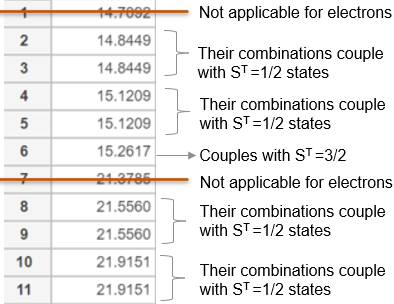

As indicated in the above table, linear superpositions of states $V(:,2)$ and $V(:,3)$ as well as superpositions of states $V(:,4)$ and $V(:,5)$ couple with spin states with $S^T=1/2$ (for both values of $M=\pm1/2$), producing four linearly independent total 3-electron wavefunctions with $S^T=1/2$ quasi-degenerate in energy with each other and with ferromagnetic quadruplet of $S^T=3/2$.

## References

[1] For hyperfine corrections in hydrogen and alkali-metal atoms see: ["Breit-Rabi diagram for alkali-metal atoms"](https://www.mathworks.com/matlabcentral/fileexchange/87819-breit-rabi-diagram-for-alkali-metal-atoms).

[2] A. Kramida, et al. ["NIST Atomic Spectra Database Ionization Energies Data"](http://physics.nist.gov/PhysRefData/ASD/ionEnergy.html). Gaithersburg, MD: NIST.

[3] R.G. Parr and W. Yang, *Density‐functional theory of atoms and molecules,* Oxford University Press, (1989).

[4] R. McWeeny,  *Methods of molecular quantum mechanics*, Academic Press Second Edition (1989).